Table for Time Point 1


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         10654         355.06           3.3362   
          2           0      5    255          1802         145.96           3.3393   
          3           0     11    255        9679.2         346.86           3.1761   
          4           0     23    255        5416.9         247.64           3.4871   
          5           0     35    255        5395.3         350.14           1.7374   
          6           0     41    255        6358.2         309.96           2.6127   
          7           0     50    255        1705.2         132.0

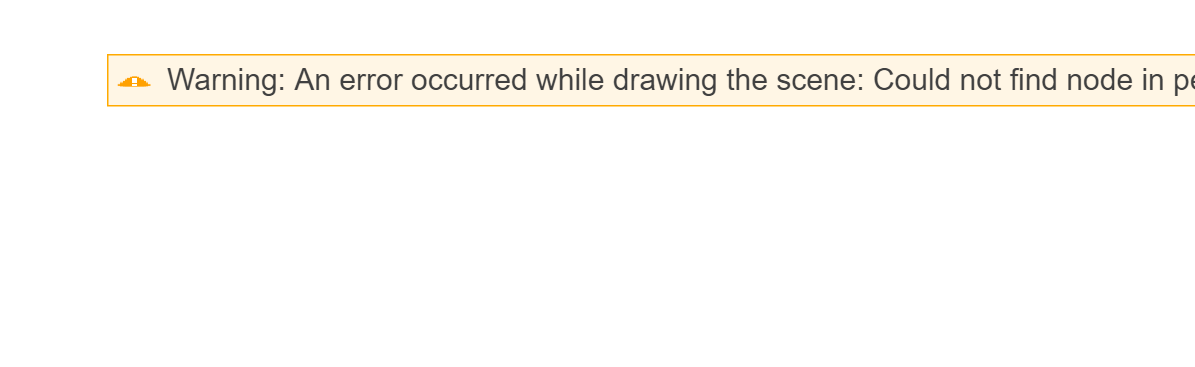

Table for Time Point 2


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         15348         564.98            1.8982  
          2           0      5    255        1574.8         133.66            3.4799  
          3           0     11    255        8033.2         322.26            3.0538  
          5           0     35    255        3001.6         177.94            3.7425  
          6           0     41    255        3265.2         195.16            3.3844  
          7           0     50    255        1233.2         112.34            3.8576  
          9           0     62    255        6442.3         269.7

Table for Time Point 3


    Region_Label     R      G      B     Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    _________    ________________    ___________

          1           0      0    255        12754         597.78             1.409  
          3           0     11    255       7906.8         323.08            2.9905  
          5           0     35    255       3449.4          192.7            3.6673  
          6           0     41    255         5439         300.12            2.3839  
          7           0     50    255       1071.1         124.64             2.722  
          9           0     62    255       5664.3         250.92            3.5517  
         12           0     86    255        13564         417.38        

Table for Time Point 4


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         10732         436.24           2.2262   
          3           0     11    255        7632.4          315.7           3.0232   
          5           0     35    255        2979.4         177.94           3.7149   
          6           0     41    255        5495.5         282.08           2.7266   
          7           0     50    255        1032.1          102.5           3.8784   
          9           0     62    255        5263.5         248.46           3.3661   
         12           0     86    255         14744         428.8

Table for Time Point 5


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         10678         421.48           2.3729   
          3           0     11    255        7288.8         304.22           3.1091   
          5           0     35    255        2518.1         162.36           3.7712   
          6           0     41    255        5188.2         264.86           2.9198   
          7           0     50    255        391.34          74.62           2.7746   
          9           0     62    255        5691.9         249.28           3.6161   
         12           0     86    255         16115          430.

Table for Time Point 6


    Region_Label     R      G      B     Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    _________    ________________    ___________

          1           0      0    255        11183         410.82            2.6158  
          3           0     11    255       7002.4         289.46            3.2993  
          5           0     35    255       1321.9         115.62             3.904  
          6           0     41    255       4437.8          241.9            2.9941  
          7           0     50    255       823.02         107.42            2.8158  
          9           0     62    255       5965.5         253.38            3.6683  
         12           0     86    255        15991         421.48        

Table for Time Point 7


    Region_Label     R      G      B      Area_um2     Circumference_um    Compactness
    ____________    ___    ___    ___    __________    ________________    ___________

          1           0      0    255         11451         405.08             2.755  
          3           0     11    255        6397.9         277.16             3.288  
          5           0     35    255        1313.2         113.16            4.0486  
          6           0     41    255          4538         239.44            3.1249  
          9           0     62    255        5875.4         249.28            3.7327  
         12           0     86    255         16875         429.68            3.6084  
         13           0     95    255        5069.2         245.1

%%% event detection code for lab on a chip setup by Tommy

% I still left the usual segmentation infront, to make sure it is done, can
% also only use second part, if segmentation is done already




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% -------- First part of Segmentation_timepoints_whole_chip ----------

% Segmentation of masks over time based on RGB values, only works with .png
% files with 32 bit depth
% updated for whole chip

% Conversion factor: 1 pixel = 0.6724 square micrometers
conversion_factor = 0.6724;  % µm² per pixel
pixel_to_micrometer = sqrt(conversion_factor);  
rgb_label_mapping = [];  
current_label_count = 0;  


file_names = { ...
    '01.png', ...
    '02.png', ...
    '03.png', ...
    '04.png', ...
    '05.png', ...
    '06.png', ...
    '07.png', ...

};

% RGB value to exclude --- grey (I want to filter out the border regions)
exclude_rgb = [128, 128, 128];

num_time_points = length(file_names);

% Loop over each time point
for t = 1:num_time_points
    
    input_image = imread(file_names{t});
    
    
    if size(input_image, 3) ~= 3
        error('Image at time point %d is not RGB. Please check the input file.', t);
    end
    
    
    [rows, cols, ~] = size(input_image);
  
    reshaped_image = reshape(input_image, [], 3);
    
    [unique_colors, ~, labels] = unique(reshaped_image, 'rows');
   
    labeled_image = reshape(labels, [rows, cols]);
    
    
    significant_labeled_image = zeros(size(input_image), 'uint8');  
    
    % Set the threshold -> removes regions, that do not fit (too small and
    % too big ones, but if the mask is done properly there should not be
    % any)
    pixel_min_threshold = 100;  
    pixel_max_threshold = 4.3309e+05;  
    
    % Initialize matrices to store pixel counts, areas, circumferences, compactness, and region labels
    pixel_counts = [];            
    areas_um2 = [];               
    circumferences_um = [];       
    compactnesses = [];           
    region_labels = [];           
    rgb_values = [];              

    % Loop through each unique region and count pixels
    for label_val = 1:max(labeled_image(:))
        
        mask = (labeled_image == label_val);
        
        
        pixel_count = sum(mask(:));
        
        
        [r, c] = find(mask);  
        if isempty(r) || isempty(c)
            continue;
        end
        
        
        current_rgb = reshape(input_image(r(1), c(1), :), 1, 3);
        
        % Skip the region if it has the RGB value [128, 128, 128] -> no
        % border
        if all(current_rgb == exclude_rgb)
            continue;
        end
        
        % Check if the region size is within the defined thresholds
        if pixel_count >= pixel_min_threshold && pixel_count <= pixel_max_threshold
            % Check if the RGB value already has an assigned label
            if isempty(rgb_label_mapping)
                % If rgb_label_mapping is empty, assign the first label
                is_existing_rgb = false;
            else
                % Check if this RGB value already has an assigned label
                [is_existing_rgb, existing_label_index] = ismember(current_rgb, rgb_label_mapping(:, 1:3), 'rows');
            end
            
            if is_existing_rgb
                
                region_label = rgb_label_mapping(existing_label_index, 4);
            else
                % Assign a new label if this RGB value is new -> new
                % cluster in case of angiogenesis
                current_label_count = current_label_count + 1;
                region_label = current_label_count;
                rgb_label_mapping = [rgb_label_mapping; current_rgb, region_label];  % Add new RGB and label to mapping
            end
            
            
            region_labels = [region_labels; region_label];
            rgb_values = [rgb_values; current_rgb]; 
            
            
            area_um2 = pixel_count * conversion_factor;  
            areas_um2 = [areas_um2; area_um2];
            
            
            perimeter_mask = bwperim(mask);
            circumference_pixels = sum(perimeter_mask(:));  
            
            
            circumference_um = circumference_pixels * pixel_to_micrometer;  
            circumferences_um = [circumferences_um; circumference_um];
            
            
            if circumference_um > 0
                compactness = area_um2 / ( (circumference_um / (2 * pi)) ^ 2 );
            else
                compactness = NaN;  % Avoid division by zero if circumference is zero
            end
            compactnesses = [compactnesses; compactness];
            
            % Calculate the centroid for placing the label
            centroid_r = round(mean(r));
            centroid_c = round(mean(c));
            
            
            significant_labeled_image(repmat(mask, [1, 1, 3])) = input_image(repmat(mask, [1, 1, 3]));
            
            
            significant_labeled_image = insertText(significant_labeled_image, [centroid_c, centroid_r], ...
                                                   num2str(region_label), 'TextColor', 'white', ...
                                                   'BoxOpacity', 0, 'FontSize', 18, 'AnchorPoint', 'Center');
        end
    end
    
    
    imwrite(significant_labeled_image, sprintf('significant_labeled_areas_timepoint_%d.png', t)); 
    
    
    output_table = table(region_labels, rgb_values(:,1), rgb_values(:,2), rgb_values(:,3), ...
        areas_um2, circumferences_um, compactnesses, ...
        'VariableNames', {'Region_Label', 'R', 'G', 'B', 'Area_um2', 'Circumference_um', 'Compactness'});
    
    
    disp(sprintf('Table for Time Point %d', t));
    disp(output_table);
    
    
    writetable(output_table, sprintf('regions_rgb_area_circumference_compactness_timepoint_%d.csv', t));
    
    
    figure;
    imshow(significant_labeled_image);
    title(sprintf('Segmented Image with Labeled Areas for Time Point %d', t));
    
end  % End of time point loop









%%%% -------- Decision tree of events -------

%based on the lists of clusters, we want to recognize 4 types of events
%with certain characteristics, which can happen for a cluster between two timepoints:

%                             Cluster
%                           /         \
%                          /           \
%                        new           gone
%                      /   \          /    \
%                     /     \        /      \
%          Angiogenesis  Spawning  Vanishing Pruning

% Angiogenesis: New blood vessel is growing, and one cluster is dividing
% into two. Condition: New cluster is appearing in second timepoint of a
% timepoint couple and on >= 50% of the pixels of the area of the new cluster
% has been a RGB value =/= 0 0 0 in the timepoint before


% Spawning: New holes appear randomly. Condition: New cluster is appearing
% in second timepoint of a timepoint couple and on <= 50% of the pixels of the area of the new cluster
% has been a RGB value = 0 0 0 in the timepoint before


% Pruning: And already existing blood vessel is retracing, and therefore an
% already existing cluster is disappreaing and merging into another
% (bigger) one. Condition: Old cluster of first timepoint of timepoint
% couple is disappearing and on the area of the old cluster there is now
% another RGB value on >= 50% of the pixels


% Vanishing: Mostly small clusters disappear over time. Condition: Old cluster of first timepoint of timepoint
% couple is disappearing and on the area of the old cluster there is now
% another RGB value on <= 50% of the pixels. So basically there should not
% be any value at all in most cases .. since 0 0 0



%%%%% Number of timepoints has to be changed manually here



num_time_points = 7; % Total number of time points
file_prefix = 'regions_rgb_area_circumference_compactness_timepoint_'; % Prefix for input tables
file_suffix = '.csv'; % File extension
image_prefix = 'significant_labeled_areas_timepoint_'; % Prefix for labeled images
image_suffix = '.png'; % File extension for images

% Loop over consecutive time points
for t = 2:num_time_points
    
    prev_table = readtable(sprintf('%s%d%s', file_prefix, t - 1, file_suffix));
    curr_table = readtable(sprintf('%s%d%s', file_prefix, t, file_suffix));
    
    
    prev_image = imread(sprintf('%s%d%s', image_prefix, t - 1, image_suffix));
    curr_image = imread(sprintf('%s%d%s', image_prefix, t, image_suffix));
    
    % Extract region labels and RGB values
    prev_labels = prev_table.Region_Label;
    prev_rgb_values = [prev_table.R, prev_table.G, prev_table.B];
    
    curr_labels = curr_table.Region_Label;
    curr_rgb_values = [curr_table.R, curr_table.G, curr_table.B];
    
    % Identify disappeared and new labels
    disappeared_labels = setdiff(prev_labels, curr_labels);
    new_labels = setdiff(curr_labels, prev_labels);
    
    % Extract RGB values for disappeared and new labels
    disappeared_rgb = prev_rgb_values(ismember(prev_labels, disappeared_labels), :);
    new_rgb = curr_rgb_values(ismember(curr_labels, new_labels), :);
    
    
    pruning_labels = [];
    vanishing_labels = [];
    pruning_rgb = [];
    vanishing_rgb = [];
    angiogenesis_labels = [];
    spawning_labels = [];
    angiogenesis_rgb = [];
    spawning_rgb = [];
    
    %%%%% Process Disappeared Labels (Pruning and Vanishing)


    for i = 1:length(disappeared_labels)
        label = disappeared_labels(i);
        rgb = disappeared_rgb(i, :);
        
        % Create a mask for the disappeared cluster in the previous image
        cluster_mask = all(prev_image == reshape(rgb, 1, 1, 3), 3);
        cluster_pixel_count = sum(cluster_mask(:));
        
        
        if size(cluster_mask, 1) ~= size(curr_image, 1) || size(cluster_mask, 2) ~= size(curr_image, 2)
            error('Mismatch in dimensions between cluster mask and current image.');
        end

        % Find the RGB values of pixels at the same coordinates in the current image
        [row_idx, col_idx] = find(cluster_mask); % Find coordinates of cluster pixels
        current_pixel_values = zeros(length(row_idx), 3);
        
        % Extract RGB values for the corresponding coordinates
        for k = 1:length(row_idx)
            current_pixel_values(k, :) = squeeze(curr_image(row_idx(k), col_idx(k), :));
        end

        % Count pixels with non-zero RGB values
        non_zero_pixels = sum(~all(current_pixel_values == 0, 2));

        % Classify the event
        if non_zero_pixels / cluster_pixel_count >= 0.5
            % Pruning: At least 50% of pixels have a new RGB value
            pruning_labels = [pruning_labels; label];
            pruning_rgb = [pruning_rgb; rgb];
        else
            % Vanishing: Less than 50% of pixels have a new RGB value
            vanishing_labels = [vanishing_labels; label];
            vanishing_rgb = [vanishing_rgb; rgb];
        end
    end
    
        %%%% Process New Labels (Angiogenesis and Spawning)


        for i = 1:length(new_labels)
            label = new_labels(i);
            rgb = new_rgb(i, :);

            % Create a mask for the new cluster in the current image
            cluster_mask = all(curr_image == reshape(rgb, 1, 1, 3), 3);
            cluster_pixel_count = sum(cluster_mask(:));

            % Ensure cluster_mask is the same size as the previous image
            if size(cluster_mask, 1) ~= size(prev_image, 1) || size(cluster_mask, 2) ~= size(prev_image, 2)
                error('Mismatch in dimensions between cluster mask and previous image.');
            end

            % Find the RGB values of pixels at the same coordinates in the previous image
            [row_idx, col_idx] = find(cluster_mask); % Find coordinates of cluster pixels

            % Ensure the cluster has valid pixel coordinates
            if isempty(row_idx) || isempty(col_idx)
                warning('Cluster with label %d and RGB [%d, %d, %d] has no valid pixels.', label, rgb);
                continue;
            end

            % Extract RGB values for the corresponding coordinates
            prev_pixel_values = zeros(length(row_idx), 3);
            for k = 1:length(row_idx)
                prev_pixel_values(k, :) = squeeze(prev_image(row_idx(k), col_idx(k), :));
            end

            % Count pixels with non-zero RGB values
            non_zero_pixels = sum(~all(prev_pixel_values == 0, 2));

            % Classify the event
            if non_zero_pixels / cluster_pixel_count >= 0.5
                % Angiogenesis: At least 50% of pixels had a previous RGB value
                angiogenesis_labels = [angiogenesis_labels; label];
                angiogenesis_rgb = [angiogenesis_rgb; rgb];
            else
            % Spawning: More than 50% of pixels were black (0, 0, 0)
                spawning_labels = [spawning_labels; label];
                spawning_rgb = [spawning_rgb; rgb];
            end
        end


%%%%%%%%%% end of decision tree



    %%%% Create tables


        pruning_table = table(pruning_labels, pruning_rgb(:, 1), pruning_rgb(:, 2), pruning_rgb(:, 3), ...
            'VariableNames', {'Label', 'R', 'G', 'B'});
        pruning_table.Event = repmat({'Pruning'}, height(pruning_table), 1);

        vanishing_table = table(vanishing_labels, vanishing_rgb(:, 1), vanishing_rgb(:, 2), vanishing_rgb(:, 3), ...
            'VariableNames', {'Label', 'R', 'G', 'B'});
        vanishing_table.Event = repmat({'Vanishing'}, height(vanishing_table), 1);

        % Add safeguards for angiogenesis and spawning tables
        if ~isempty(angiogenesis_labels) && ~isempty(angiogenesis_rgb)
            angiogenesis_table = table(angiogenesis_labels, angiogenesis_rgb(:, 1), angiogenesis_rgb(:, 2), angiogenesis_rgb(:, 3), ...
                'VariableNames', {'Label', 'R', 'G', 'B'});
            angiogenesis_table.Event = repmat({'Angiogenesis'}, height(angiogenesis_table), 1);
        else
            angiogenesis_table = table([], [], [], [], {}, 'VariableNames', {'Label', 'R', 'G', 'B', 'Event'});
        end

        if ~isempty(spawning_labels) && ~isempty(spawning_rgb)
            spawning_table = table(spawning_labels, spawning_rgb(:, 1), spawning_rgb(:, 2), spawning_rgb(:, 3), ...
                'VariableNames', {'Label', 'R', 'G', 'B'});
            spawning_table.Event = repmat({'Spawning'}, height(spawning_table), 1);
        else
            spawning_table = table([], [], [], [], {}, 'VariableNames', {'Label', 'R', 'G', 'B', 'Event'});
        end


        % Combine all event tables
        combined_table = [pruning_table; vanishing_table; angiogenesis_table; spawning_table];

        
        output_file = sprintf('timepoint_event_comparison_%d_to_%d.csv', t - 1, t);
        writetable(combined_table, output_file);

        
        disp(['Comparison between Time Point ', num2str(t - 1), ' and Time Point ', num2str(t)]);
        disp(combined_table);

end

Comparison between Time Point 1 and Time Point 2


    Label     R      G      B          Event      
    _____    ___    ___    ___    ________________

       4       0     23    255    {'Pruning'     }
      17       0    110    255    {'Pruning'     }
      25       0    138      0    {'Pruning'     }
      28       0    146    255    {'Pruning'     }
     138     153    100      0    {'Pruning'     }
     158     255     46      0    {'Pruning'     }
       8       0     56    255    {'Vanishing'   }
      10       0     71    255    {'Vanishing'   }
      11       0     80    255    {'Vanishing'   }
      14       0    100      0    {'Vanishing'   }
      16       0    105      0    {'Vanishing'   }
      30       0    152    255    {'Vanishing'   }
      42       0    188    255    {'Vanishing'   }
      46       0    200    255    {'Vanishing'   }
      51     

Comparison between Time Point 2 and Time Point 3


    Label     R      G      B          Event      
    _____    ___    ___    ___    ________________

      15       0    101    255    {'Pruning'     }
      48       0    204      0    {'Pruning'     }
      59       0    239    255    {'Pruning'     }
      67       0    255     12    {'Pruning'     }
     169     255      0     12    {'Pruning'     }
     170     255      0     18    {'Pruning'     }
     171     255      0     24    {'Pruning'     }
     177     255      0     51    {'Pruning'     }
     184     255      0     72    {'Pruning'     }
     192     255      0     99    {'Pruning'     }
     195     255      0    114    {'Pruning'     }
       2       0      5    255    {'Vanishing'   }
      33       0    159      0    {'Vanishing'   }
     100       0    255    180    {'Vanishing'   }
     104     

Comparison between Time Point 3 and Time Point 4


    Label     R      G      B          Event      
    _____    ___    ___    ___    ________________

      71       0    255     36    {'Pruning'     }
     131     111    100      0    {'Pruning'     }
     160     255      0     66    {'Pruning'     }
     182     255      0     78    {'Pruning'     }
     186     255      0     84    {'Pruning'     }
     193     255      0    117    {'Pruning'     }
      23       0    126      0    {'Vanishing'   }
      45       0    197    255    {'Vanishing'   }
      54       0    222      0    {'Vanishing'   }
     112       0    255    255    {'Vanishing'   }
     123      63    100      0    {'Vanishing'   }
     124      69    100      0    {'Vanishing'   }
     132     117    100      0    {'Vanishing'   }
     188     255      0     87    {'Vanishing'   }
     189     

Comparison between Time Point 4 and Time Point 5


    Label     R      G      B          Event      
    _____    ___    ___    ___    ________________

     120      45    100      0    {'Pruning'     }
     128      93    100      0    {'Pruning'     }
     211     255      0    173    {'Pruning'     }
     218     255      0    203    {'Pruning'     }
     224     255      0    224    {'Pruning'     }
     227     255      0    233    {'Pruning'     }
     228     255      0    236    {'Pruning'     }
      74       0    255     54    {'Vanishing'   }
     176     255      0     48    {'Vanishing'   }
     210     255      0    170    {'Vanishing'   }
     217     255      0    200    {'Vanishing'   }
     225     255      0    227    {'Vanishing'   }
     229     255      0    239    {'Vanishing'   }
     239     255     15    255    {'Angiogenesis'}
     242     

Comparison between Time Point 5 and Time Point 6


    Label     R      G      B         Event    
    _____    ___    ___    ___    _____________

     113       6    100      0    {'Pruning'  }
     125      75    100      0    {'Pruning'  }
     231     255      0    245    {'Pruning'  }
     242     255     24    255    {'Pruning'  }
      88       0    255    129    {'Vanishing'}
      89       0    255    132    {'Vanishing'}
      96       0    255    156    {'Vanishing'}
     103       0    255    198    {'Vanishing'}
     175     255      0     45    {'Vanishing'}
     200     255      0    129    {'Vanishing'}
     202     255      0    135    {'Vanishing'}
     237     255      9    255    {'Vanishing'}
     240     255     18    255    {'Vanishing'}
     241     255     21    255    {'Vanishing'}
     243     255      0    250    {'Spawning' }



Comparison between Time Point 6 and Time Point 7


    Label     R      G      B          Event      
    _____    ___    ___    ___    ________________

      44       0    195      0    {'Pruning'     }
     191     255      0     96    {'Pruning'     }
     226     255      0    230    {'Pruning'     }
       7       0     50    255    {'Vanishing'   }
      83       0    255    105    {'Vanishing'   }
     117      27    100      0    {'Vanishing'   }
     151     231    100      0    {'Vanishing'   }
     213     255      0    182    {'Vanishing'   }
     232     255      0    247    {'Vanishing'   }
     235     255      0    250    {'Vanishing'   }
     236     255      3    255    {'Vanishing'   }
     238     255      6    255    {'Vanishing'   }
     243     255     12    255    {'Vanishing'   }
     231     218    235    254    {'Angiogenesis'}
     247     

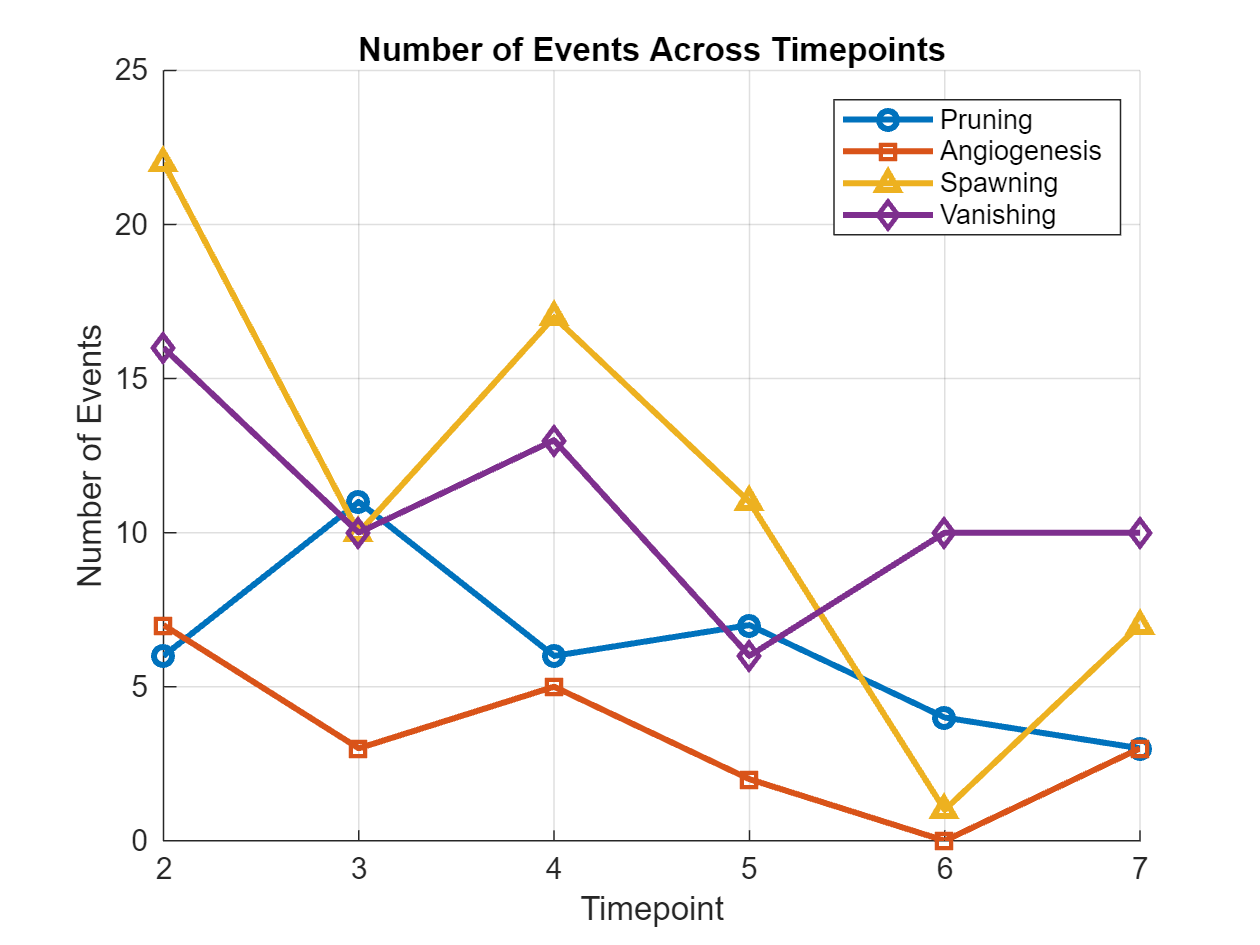




%%% Diagram which shows how many events happen at each timepoint



% Again adjust timepoints manually
num_time_points = 7;


pruning_counts = zeros(1, num_time_points - 1);
angiogenesis_counts = zeros(1, num_time_points - 1);
spawning_counts = zeros(1, num_time_points - 1);
vanishing_counts = zeros(1, num_time_points - 1);

% Loop through each timepoint pair and read the corresponding table
for t = 2:num_time_points
    % Load the table for the current timepoint pair
    input_file = sprintf('timepoint_event_comparison_%d_to_%d.csv', t - 1, t);
    event_table = readtable(input_file);
    
    % Count the occurrences of each event
    pruning_counts(t - 1) = sum(strcmp(event_table.Event, 'Pruning'));
    angiogenesis_counts(t - 1) = sum(strcmp(event_table.Event, 'Angiogenesis'));
    spawning_counts(t - 1) = sum(strcmp(event_table.Event, 'Spawning'));
    vanishing_counts(t - 1) = sum(strcmp(event_table.Event, 'Vanishing'));
end


timepoint_pairs = 2:num_time_points;

% Plot
figure;
hold on;
plot(timepoint_pairs, pruning_counts, '-o', 'LineWidth', 2, 'DisplayName', 'Pruning');
plot(timepoint_pairs, angiogenesis_counts, '-s', 'LineWidth', 2, 'DisplayName', 'Angiogenesis');
plot(timepoint_pairs, spawning_counts, '-^', 'LineWidth', 2, 'DisplayName', 'Spawning');
plot(timepoint_pairs, vanishing_counts, '-d', 'LineWidth', 2, 'DisplayName', 'Vanishing');
hold off;


xlabel('Timepoint');
ylabel('Number of Events');
title('Number of Events Across Timepoints');
legend('Location', 'best');
grid on;


xticks(timepoint_pairs);
xlim([min(timepoint_pairs) max(timepoint_pairs)]);



%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% end of current version




%New update: Coordinate determination of events 

%1. Pruning 

%% 1. get x-coordinates of Pruning events
% I do look at the cluster coordinates which are marked as pruning events
% and then look at the next timepoint to see which cluster number is the
% consuming cluster -> look at first timepoint again and find the pixels
% which are part of the pruning by drawing a connection there



for t = 2:num_time_points
    fprintf('Processing timepoints %d+%d...\n', t-1, t);  % Debugging output

    
    pruning_table = readtable(sprintf('timepoint_event_comparison_%d_to_%d.csv', t - 1, t));

    % Filter only pruning
    pruning_table = pruning_table(strcmp(pruning_table.Event, 'Pruning'), :);

    
    prev_image = imread(sprintf('%s%d%s', image_prefix, t - 1, image_suffix));
    curr_image = imread(sprintf('%s%d%s', image_prefix, t, image_suffix));

    
    pruning_x_coordinates = cell(height(pruning_table), 1);
    for i = 1:height(pruning_table)
        rgb_disappeared = [pruning_table.R(i), pruning_table.G(i), pruning_table.B(i)];
        disappeared_mask = all(prev_image == reshape(rgb_disappeared, 1, 1, 3), 3);

        if any(disappeared_mask(:))
            % Find border pixels of disappeared cluster
            border_disappeared = bwperim(disappeared_mask);
            [dis_row, dis_col] = find(border_disappeared);

            % Determine the consuming cluster
            sample_rgb_values = zeros(length(dis_row), 3);
            for k = 1:length(dis_row)
                sample_rgb_values(k, :) = squeeze(curr_image(dis_row(k), dis_col(k), :));
            end
            absorbing_rgb = mode(sample_rgb_values, 1);
            absorbing_mask = all(curr_image == reshape(absorbing_rgb, 1, 1, 3), 3);
            border_absorbing = bwperim(absorbing_mask);
            [abs_row, abs_col] = find(border_absorbing);

            % Calculate distances between border pixels
            distances = pdist2([dis_row, dis_col], [abs_row, abs_col]);
            [~, idx] = min(distances, [], 2);

            %
            pruning_x_coordinates{i} = [dis_col, abs_col(idx)];
        else
            pruning_x_coordinates{i} = [];
        end
    end

    
    pruning_event_summary = cell(height(pruning_table), 3);
    for i = 1:height(pruning_table)
        if isempty(pruning_x_coordinates{i})
            coords_str = 'No coordinates found';
        else
            coords_str = mat2str(pruning_x_coordinates{i}(:, 1)');
        end

        
        pruning_event_summary{i, 1} = sprintf('Timepoints %d+%d', t - 1, t);
        pruning_event_summary{i, 2} = pruning_table.Label(i);
        pruning_event_summary{i, 3} = coords_str;
    end

    % Convert cell array to table for current timepoint pair
    summary_table = cell2table(pruning_event_summary, 'VariableNames', {'Timepoints', 'Pruning_Event', 'X_Coordinates'});

    % Display and save the summary table for current timepoint pair
    disp(summary_table);
    writetable(summary_table, sprintf('pruning_event_summary_%d_%d.csv', t - 1, t));

end

Processing timepoints 1+2...


        Timepoints        Pruning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Processing timepoints 2+3...


        Timepoints        Pruning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Processing timepoints 3+4...


        Timepoints        Pruning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

Processing timepoints 4+5...


        Timepoints        Pruning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Processing timepoints 5+6...


        Timepoints        Pruning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Processing timepoints 6+7...


        Timepoints        Pruning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               


% Merge all individual CSV files after processing
all_data = [];

for t = 2:num_time_points
    curr_data = readtable(sprintf('pruning_event_summary_%d_%d.csv', t - 1, t));

    % Ensure the table has the correct column names
    expected_vars = {'Timepoints', 'Pruning_Event', 'X_Coordinates'};
    
   % Add missing columns if necessary
    for v = expected_vars
        if ~ismember(v, curr_data.Properties.VariableNames)
            curr_data.(v{1}) = repmat({''}, height(curr_data), 1); % Fill missing column with empty strings
        end
    end


    % Ensure the table has the correct column names and data types
    expected_vars = {'Timepoints', 'Pruning_Event', 'X_Coordinates'};

    % Convert columns to string format to ensure consistency
    for v = expected_vars
        if ismember(v, curr_data.Properties.VariableNames)
            % Check if the column contains numeric values
            if isnumeric(curr_data.(v{1}))
                curr_data.(v{1}) = cellstr(num2str(curr_data.(v{1})));  % Convert numeric to string and then to cell
            else
                curr_data.(v{1}) = cellstr(curr_data.(v{1}));  % Convert to cell array of strings
            end
        else
            curr_data.(v{1}) = repmat({''}, height(curr_data), 1);  % Add missing columns as empty strings
        end
    end


curr_data = curr_data(:, expected_vars);


all_data = [all_data; curr_data];

end


writetable(all_data, 'final_pruning_event_summary.csv');
disp('Final pruning event summary saved.');

Final pruning event summary saved.






% combining all tables to a compact table of all unique x-coordinates of
% pruning


% file is called: compact_pruning.csv

% this part only works in python so far, here is the code for that 

%{




%}

% Loading the compact csv file


% Load the compact pruning summary CSV file
filename = 'compact_pruning.csv';

% Read the table
compact_table = readtable(filename, 'Delimiter', ',', 'TextType', 'string');

% Display the loaded table
disp('Loaded compact pruning summary:');

Loaded compact pruning summary:


disp(compact_table);

      Timepoints                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       


%{

%Visualization

% Load the compact pruning summary CSV file
compact_data = readtable('compact_pruning.csv');

% Extract unique timepoints and coordinates
timepoints = compact_data.Timepoints;
x_coordinates = compact_data.Unique_X_Coordinates;

% Convert x-coordinates from string to numerical arrays
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Define color palette
colors = lines(length(timepoints));

% Create the figure
figure;
hold on;
for t = 1:length(timepoints)
    y_level = length(timepoints) - t + 1; % Stack from top to bottom
    coords = x_coords_numeric{t};

    % Plot vertical bars for each coordinate at the corresponding timepoint level
    for j = 1:length(coords)
        plot([coords(j), coords(j)], [y_level-0.4, y_level+0.4], ...
            'Color', colors(t, :), 'LineWidth', 5); 
    end
end

% Configure plot appearance
yticks(1:length(timepoints));
yticklabels(flip(timepoints));  % Label each stacked axis
xlabel('X-Coordinates (pixels)');
ylabel('Timepoint Pairs');
title('Pruning Events Visualization');
xlim([0 max(cellfun(@(x) max(str2num(x)), x_coordinates)) + 100]); % Adjust x-limits
hold off;

disp('Plotting complete.');

%}
%end of the pruning coordinate extraction %%%%%%%%%%%%%%%%%%%%%%





%2. whole ting for sprouting angiogenesis
% nstead of looking at disappeared clusters, this looks at newly appearing clusters in the next timepoint.
% Finds the originating cluster in the previous timepoint



%% 1. Get x-coordinates of Angiogenesis events
% Loop through each timepoint pair
for t = 2:num_time_points
    fprintf('Processing timepoints %d+%d...\n', t-1, t);  % Debugging output

    % Read the angiogenesis event table for the current pair
    angiogenesis_table = readtable(sprintf('timepoint_event_comparison_%d_to_%d.csv', t - 1, t));

    % Filter only angiogenesis events
    angiogenesis_table = angiogenesis_table(strcmp(angiogenesis_table.Event, 'Angiogenesis'), :);

    % Load corresponding images
    prev_image = imread(sprintf('%s%d%s', image_prefix, t - 1, image_suffix));
    curr_image = imread(sprintf('%s%d%s', image_prefix, t, image_suffix));

    % Extract x-coordinates for angiogenesis events
    angiogenesis_x_coordinates = cell(height(angiogenesis_table), 1);
    for i = 1:height(angiogenesis_table)
        rgb_appeared = [angiogenesis_table.R(i), angiogenesis_table.G(i), angiogenesis_table.B(i)];
        appeared_mask = all(curr_image == reshape(rgb_appeared, 1, 1, 3), 3);

        if any(appeared_mask(:))
            % Find border pixels of the new cluster
            border_appeared = bwperim(appeared_mask);
            [app_row, app_col] = find(border_appeared);

            % Determine the originating cluster in the previous timepoint
            sample_rgb_values = zeros(length(app_row), 3);
            for k = 1:length(app_row)
                sample_rgb_values(k, :) = squeeze(prev_image(app_row(k), app_col(k), :));
            end
            originating_rgb = mode(sample_rgb_values, 1);
            originating_mask = all(prev_image == reshape(originating_rgb, 1, 1, 3), 3);
            border_originating = bwperim(originating_mask);
            [org_row, org_col] = find(border_originating);

            % Calculate distances between border pixels
            distances = pdist2([app_row, app_col], [org_row, org_col]);
            [~, idx] = min(distances, [], 2);

            % Store x-coordinates of both cluster borders
            angiogenesis_x_coordinates{i} = [app_col, org_col(idx)];
        else
            angiogenesis_x_coordinates{i} = [];
        end
    end

    % Create table for current timepoint pair
    angiogenesis_event_summary = cell(height(angiogenesis_table), 3);
    for i = 1:height(angiogenesis_table)
        if isempty(angiogenesis_x_coordinates{i})
            coords_str = 'No coordinates found';
        else
            coords_str = mat2str(angiogenesis_x_coordinates{i}(:, 1)');
        end

        % Store the data for each angiogenesis event
        angiogenesis_event_summary{i, 1} = sprintf('Timepoints %d+%d', t - 1, t);
        angiogenesis_event_summary{i, 2} = angiogenesis_table.Label(i);
        angiogenesis_event_summary{i, 3} = coords_str;
    end

    % Convert cell array to table for current timepoint pair
    summary_table = cell2table(angiogenesis_event_summary, 'VariableNames', {'Timepoints', 'Angiogenesis_Event', 'X_Coordinates'});

    % Display and save the summary table for current timepoint pair
    disp(summary_table);
    writetable(summary_table, sprintf('angiogenesis_event_summary_%d_%d.csv', t - 1, t));

end

Processing timepoints 1+2...


        Timepoints        Angiogenesis_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

Processing timepoints 2+3...


        Timepoints        Angiogenesis_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

Processing timepoints 3+4...


        Timepoints        Angiogenesis_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

Processing timepoints 4+5...


        Timepoints        Angiogenesis_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   X_Coordinates                         

Processing timepoints 5+6...


    Timepoints    Angiogenesis_Event    X_Coordinates
    __________    __________________    _____________




Processing timepoints 6+7...


        Timepoints        Angiogenesis_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     X_Coordinates       

%}

%combining the csv files has again to be done in python so far ... thanks
%matlab

%{
import pandas as pd
import re

# List of input CSV files
file_list = [
    'angiogenesis_event_summary_1_2.csv',
    'angiogenesis_event_summary_2_3.csv',
    'angiogenesis_event_summary_3_4.csv',
    'angiogenesis_event_summary_4_5.csv',
    'angiogenesis_event_summary_5_6.csv',
    'angiogenesis_event_summary_6_7.csv'
]

# Initialize an empty list to store summary data
compact_summary = []

# Process each file
for file in file_list:
    df = pd.read_csv(file)

    # Extract timepoint in the format "Timepoint 1+2" using regex
    match = re.search(r'(\d+)_(\d+)', file)
    if match:
        timepoint = f"Timepoint {match.group(1)}+{match.group(2)}"
    else:
        raise ValueError(f"Could not extract timepoints from filename: {file}")

    # Convert X_Coordinates column from string to list of numbers
    df['X_Coordinates'] = df['X_Coordinates'].apply(lambda x: list(map(int, x.strip('[]').split())))

    # Get unique x-values
    unique_x_values = sorted(set(x for sublist in df['X_Coordinates'] for x in sublist))

    # Store the compact summary
    compact_summary.append([timepoint, unique_x_values])

# Convert to DataFrame
compact_df = pd.DataFrame(compact_summary, columns=['Timepoints', 'Unique_X_Coordinates'])

# Save the compact summary to CSV
compact_file_path = 'compact_angiogenesis.csv'
compact_df.to_csv(compact_file_path, index=False)

print(f'Compact angiogenesis summary saved as {compact_file_path}')



%}


%{

% Load and process compact summary
compact_data = readtable('compact_angiogenesis.csv');

% Extract unique timepoints and coordinates
timepoints = compact_data.Timepoints;
x_coordinates = compact_data.Unique_X_Coordinates;

% Convert x-coordinates from string to numerical arrays
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Define color palette
colors = lines(length(timepoints));

% Create the figure
figure;
hold on;
for t = 1:length(timepoints)
    y_level = length(timepoints) - t + 1; % Stack from top to bottom
    coords = x_coords_numeric{t};

    % Plot vertical bars for each coordinate at the corresponding timepoint level
    for j = 1:length(coords)
        plot([coords(j), coords(j)], [y_level-0.4, y_level+0.4], ...
            'Color', colors(t, :), 'LineWidth', 5); 
    end
end



% Configure plot appearance
yticks(1:length(timepoints));
yticklabels(flip(timepoints));  % Label each stacked axis
xlabel('X-Coordinates (pixels)');
ylabel('Timepoint Pairs');
title('Angiogenesis Events Visualization');

% Convert x-coordinates from string to numerical arrays safely
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Remove empty cells and convert remaining ones to numeric arrays
x_coords_numeric = x_coords_numeric(~cellfun('isempty', x_coords_numeric));

% Flatten the cell array to get all coordinates and determine x-axis limits
all_coords = cell2mat(x_coords_numeric);
xlim([0 max(all_coords) + 100]);


grid on;
hold off;

disp('Plotting complete.');

%}



%3. Spawning / non-sprouting angiogenesis
% for that we just look at a timepoint pair and look which clusters were
% assigned to spawning by the decision tree and then look at the second
% timepoint and take all the x-coordinates of the 


% Spawning Event X-Coordinates Extraction

% Loop through each timepoint pair
for t = 2:num_time_points
    fprintf('Processing timepoints %d+%d...\n', t-1, t);  % Debugging output

    % Read the event table for the current pair
    spawning_table = readtable(sprintf('timepoint_event_comparison_%d_to_%d.csv', t - 1, t));

    % Filter only spawning events
    spawning_table = spawning_table(strcmp(spawning_table.Event, 'Spawning'), :);

    % Load corresponding images
    curr_image = imread(sprintf('%s%d%s', image_prefix, t, image_suffix));

    % Extract x-coordinates for spawning events
    spawning_x_coordinates = cell(height(spawning_table), 1);
    for i = 1:height(spawning_table)
        rgb_spawned = [spawning_table.R(i), spawning_table.G(i), spawning_table.B(i)];
        spawned_mask = all(curr_image == reshape(rgb_spawned, 1, 1, 3), 3);

        if any(spawned_mask(:))
            % Find all pixel locations of the spawned cluster
            [spawn_row, spawn_col] = find(spawned_mask);

            % Store x-coordinates
            spawning_x_coordinates{i} = spawn_col;
        else
            spawning_x_coordinates{i} = [];
        end
    end

    % Create table for current timepoint pair
    spawning_event_summary = cell(height(spawning_table), 3);
    for i = 1:height(spawning_table)
        if isempty(spawning_x_coordinates{i})
            coords_str = 'No coordinates found';
        else
            coords_str = mat2str(spawning_x_coordinates{i}');
        end

        % Store the data for each spawning event
        spawning_event_summary{i, 1} = sprintf('Timepoints %d+%d', t - 1, t);
        spawning_event_summary{i, 2} = spawning_table.Label(i);
        spawning_event_summary{i, 3} = coords_str;
    end

    % Convert cell array to table for current timepoint pair
    summary_table = cell2table(spawning_event_summary, 'VariableNames', {'Timepoints', 'Spawning_Event', 'X_Coordinates'});

    % Display and save the summary table for current timepoint pair
    disp(summary_table);
    writetable(summary_table, sprintf('spawning_event_summary_%d_%d.csv', t - 1, t));

end

Processing timepoints 1+2...


        Timepoints        Spawning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Processing timepoints 2+3...


        Timepoints        Spawning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Processing timepoints 3+4...


        Timepoints        Spawning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Processing timepoints 4+5...


        Timepoints        Spawning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Processing timepoints 5+6...


        Timepoints        Spawning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

Processing timepoints 6+7...


        Timepoints        Spawning_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              

disp('Spawning event extraction completed.');

Spawning event extraction completed.



%next python code again

%{

import pandas as pd
import re

# List of input CSV files
file_list = [
    'spawning_event_summary_1_2.csv',
    'spawning_event_summary_2_3.csv',
    'spawning_event_summary_3_4.csv',
    'spawning_event_summary_4_5.csv',
    'spawning_event_summary_5_6.csv',
    'spawning_event_summary_6_7.csv'
]

# Initialize an empty list to store summary data
compact_summary = []

# Process each file
for file in file_list:
    df = pd.read_csv(file)

    # Extract timepoint in the format "Timepoint 1+2" using regex
    match = re.search(r'(\d+)_(\d+)', file)
    if match:
        timepoint = f"Timepoint {match.group(1)}+{match.group(2)}"
    else:
        raise ValueError(f"Could not extract timepoints from filename: {file}")

    # Convert X_Coordinates column from string to list of numbers
    df['X_Coordinates'] = df['X_Coordinates'].apply(lambda x: list(map(int, x.strip('[]').split())))

    # Get unique x-values
    unique_x_values = sorted(set(x for sublist in df['X_Coordinates'] for x in sublist))

    # Store the compact summary
    compact_summary.append([timepoint, unique_x_values])

# Convert to DataFrame
compact_df = pd.DataFrame(compact_summary, columns=['Timepoints', 'Unique_X_Coordinates'])

# Save the compact summary to CSV
compact_file_path = 'compact_spawning.csv'
compact_df.to_csv(compact_file_path, index=False)

print(f'Compact spawning summary saved as {compact_file_path}')


%}


%{

% Load and process compact spawning summary
compact_data = readtable('compact_spawning.csv');

% Extract unique timepoints and coordinates
timepoints = compact_data.Timepoints;
x_coordinates = compact_data.Unique_X_Coordinates;

% Convert x-coordinates from string to numerical arrays safely
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Remove empty cells and convert remaining ones to numeric arrays
x_coords_numeric = x_coords_numeric(~cellfun('isempty', x_coords_numeric));

% Flatten the cell array to get all coordinates and determine x-axis limits
% Flatten the cell array safely by handling inconsistent sizes
all_coords = [];
for i = 1:length(x_coords_numeric)
    if isnumeric(x_coords_numeric{i}) && ~isempty(x_coords_numeric{i})
        all_coords = [all_coords, x_coords_numeric{i}(:)']; 
    end
end


% Define color palette
colors = lines(length(timepoints));

% Create the figure
figure;
hold on;
for t = 1:length(timepoints)
    y_level = length(timepoints) - t + 1; % Stack from top to bottom
    coords = x_coords_numeric{t};

    % Plot vertical bars for each coordinate at the corresponding timepoint level
    for j = 1:length(coords)
        plot([coords(j), coords(j)], [y_level-0.4, y_level+0.4], ...
            'Color', colors(t, :), 'LineWidth', 5); 
    end
end

% Configure plot appearance
yticks(1:length(timepoints));
yticklabels(flip(timepoints));  % Label each stacked axis
xlabel('X-Coordinates (pixels)');
ylabel('Timepoint Pairs');
title('Spawning Events Visualization');
xlim([0 max(all_coords) + 100]);
grid off;
hold off;

disp('Plotting complete.');

%}
%%%%%%%%%%%%




% 4. Vanishing, just like spawning but looking at first timepoint

% 1. Extract x-coordinates of Vanishing events
for t = 2:num_time_points
    fprintf('Processing timepoints %d+%d...\n', t-1, t);  % Debugging output

    % Read the vanishing event table for the current pair
    vanishing_table = readtable(sprintf('timepoint_event_comparison_%d_to_%d.csv', t - 1, t));

    % Filter only vanishing events
    vanishing_table = vanishing_table(strcmp(vanishing_table.Event, 'Vanishing'), :);

    % Load corresponding images for first timepoint
    prev_image = imread(sprintf('%s%d%s', image_prefix, t - 1, image_suffix));

    % Extract x-coordinates for vanishing events
    vanishing_x_coordinates = cell(height(vanishing_table), 1);
    for i = 1:height(vanishing_table)
        rgb_vanished = [vanishing_table.R(i), vanishing_table.G(i), vanishing_table.B(i)];
        vanished_mask = all(prev_image == reshape(rgb_vanished, 1, 1, 3), 3);

        if any(vanished_mask(:))
            % Find all x-coordinates of the vanished cluster
            [row, col] = find(vanished_mask);
            vanishing_x_coordinates{i} = col;  % Store x-coordinates
        else
            vanishing_x_coordinates{i} = [];
        end
    end

    % Create table for current timepoint pair
    vanishing_event_summary = cell(height(vanishing_table), 3);
    for i = 1:height(vanishing_table)
        if isempty(vanishing_x_coordinates{i})
            coords_str = 'No coordinates found';
        else
            coords_str = mat2str(vanishing_x_coordinates{i}');
        end

        % Store the data for each vanishing event
        vanishing_event_summary{i, 1} = sprintf('Timepoints %d+%d', t - 1, t);
        vanishing_event_summary{i, 2} = vanishing_table.Label(i);
        vanishing_event_summary{i, 3} = coords_str;
    end

    % Convert cell array to table for current timepoint pair
    summary_table = cell2table(vanishing_event_summary, 'VariableNames', {'Timepoints', 'Vanishing_Event', 'X_Coordinates'});

    % Display and save the summary table for current timepoint pair
    disp(summary_table);
    writetable(summary_table, sprintf('vanishing_event_summary_%d_%d.csv', t - 1, t));
end

Processing timepoints 1+2...


        Timepoints        Vanishing_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

Processing timepoints 2+3...


        Timepoints        Vanishing_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

Processing timepoints 3+4...


        Timepoints        Vanishing_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

Processing timepoints 4+5...


        Timepoints        Vanishing_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

Processing timepoints 5+6...


        Timepoints        Vanishing_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

Processing timepoints 6+7...


        Timepoints        Vanishing_Event                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

disp('Vanishing event extraction completed.');

Vanishing event extraction completed.


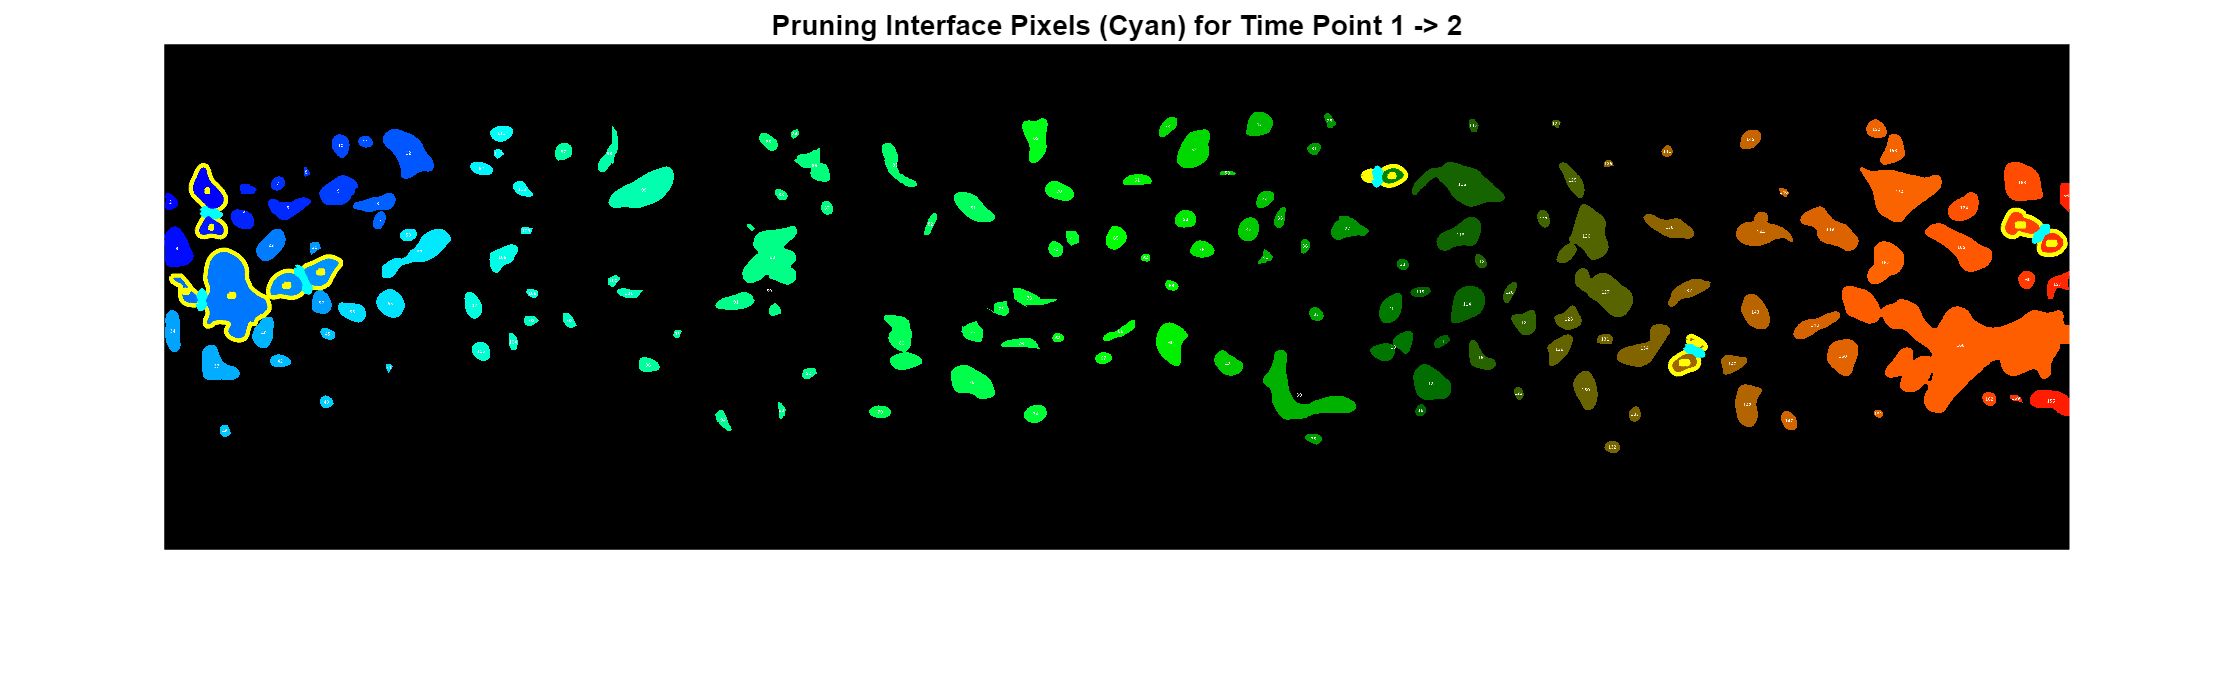

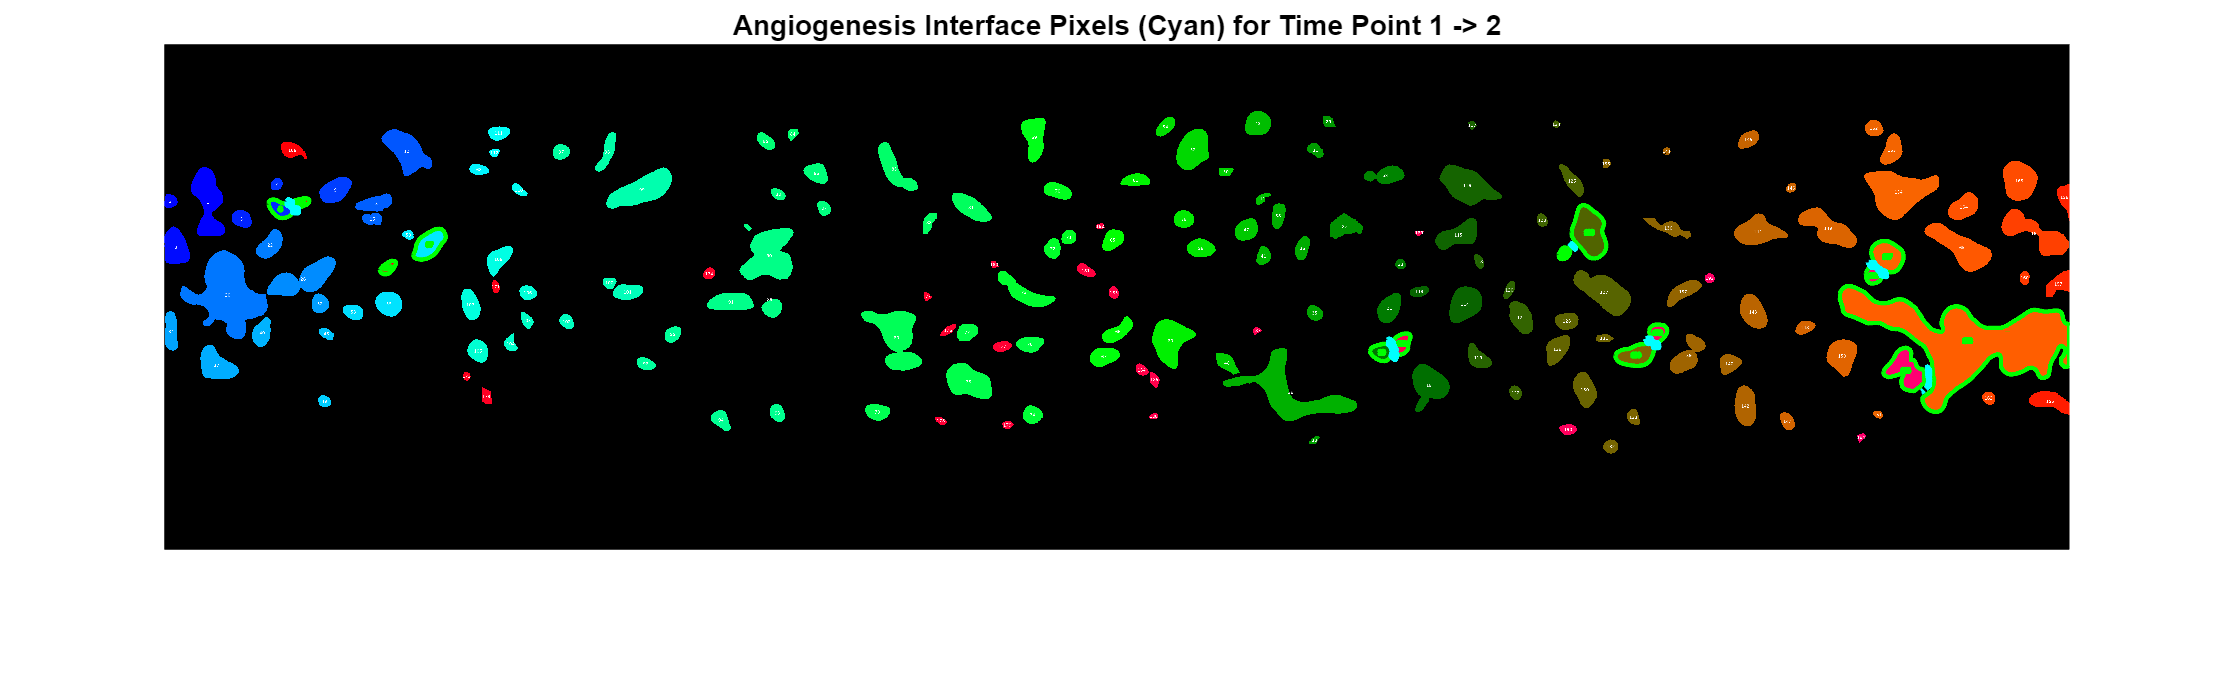

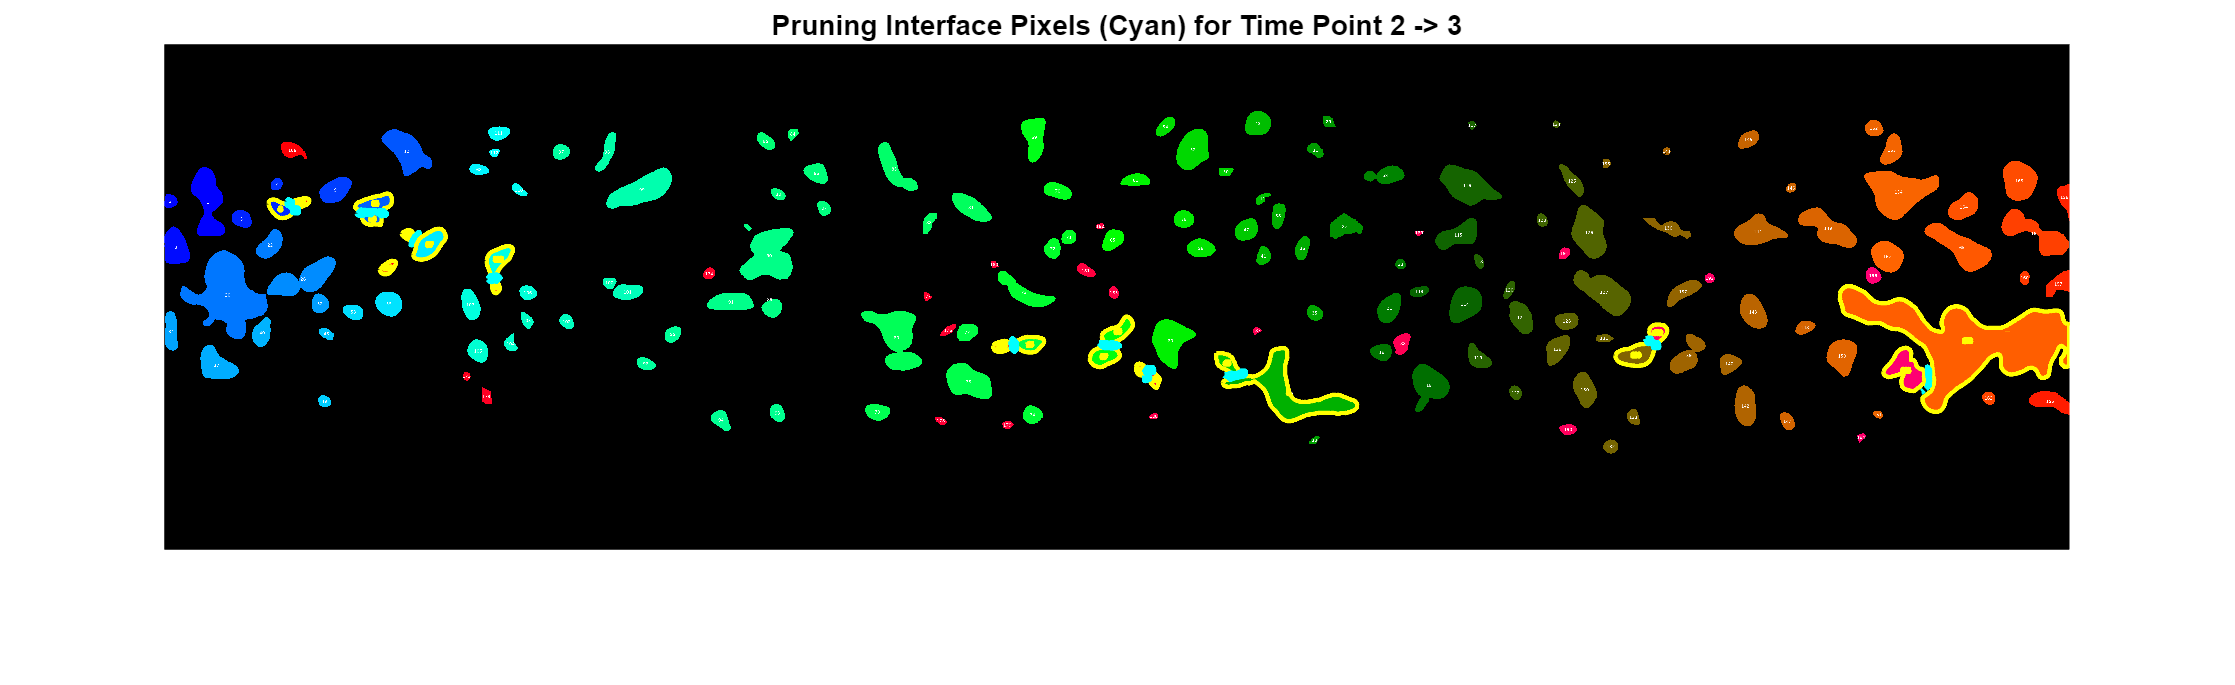

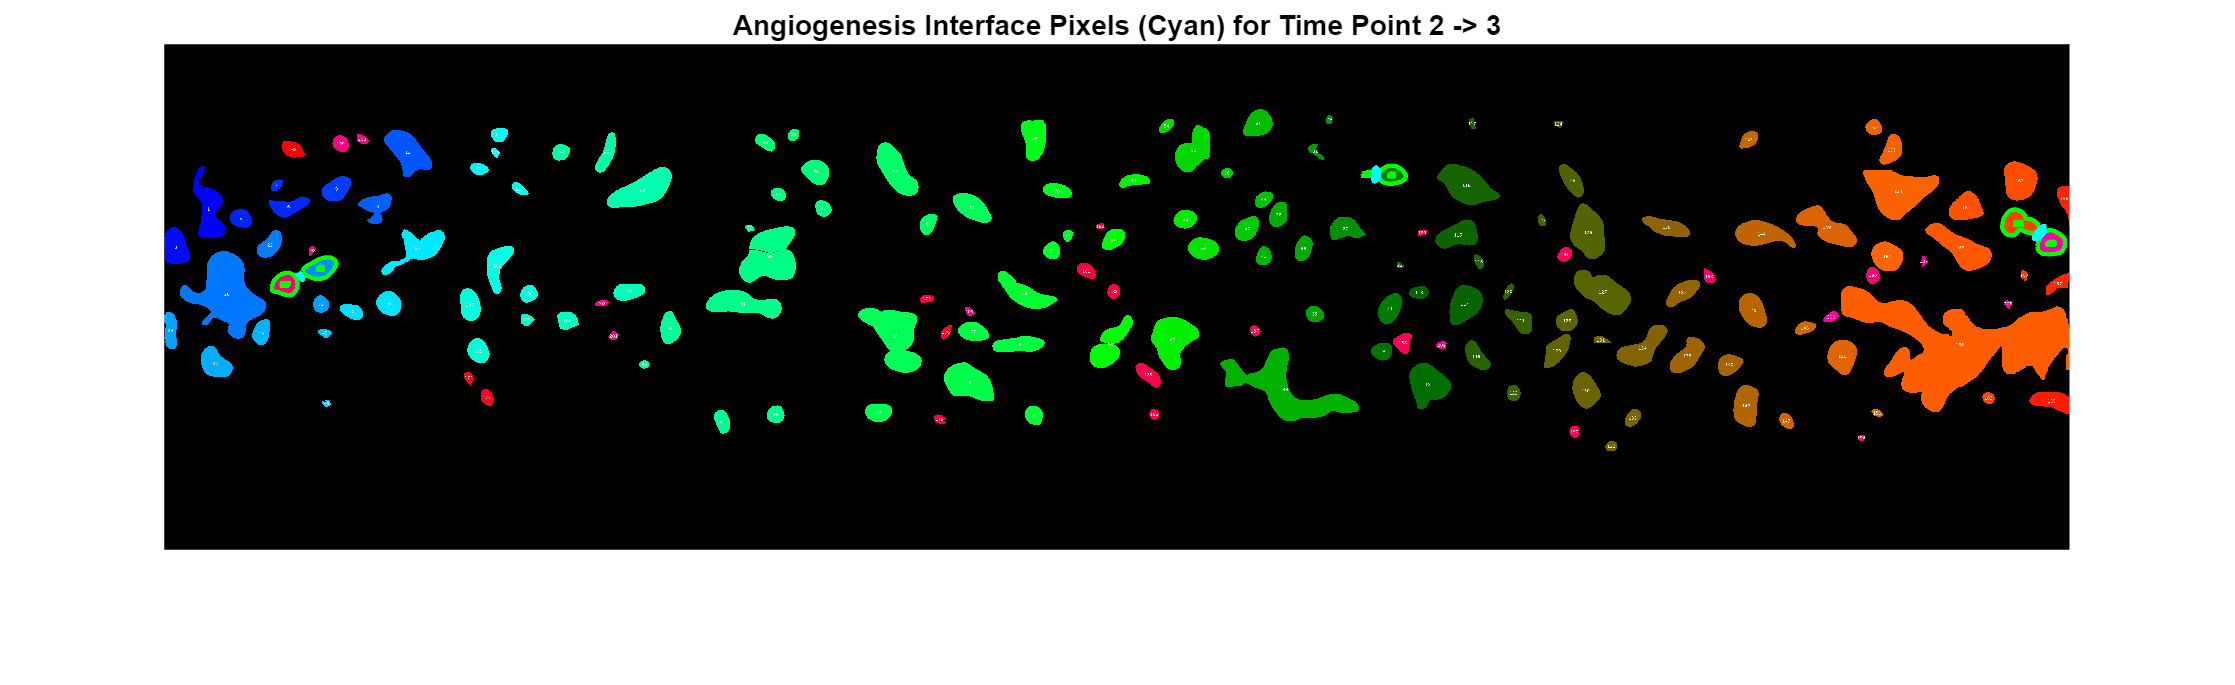

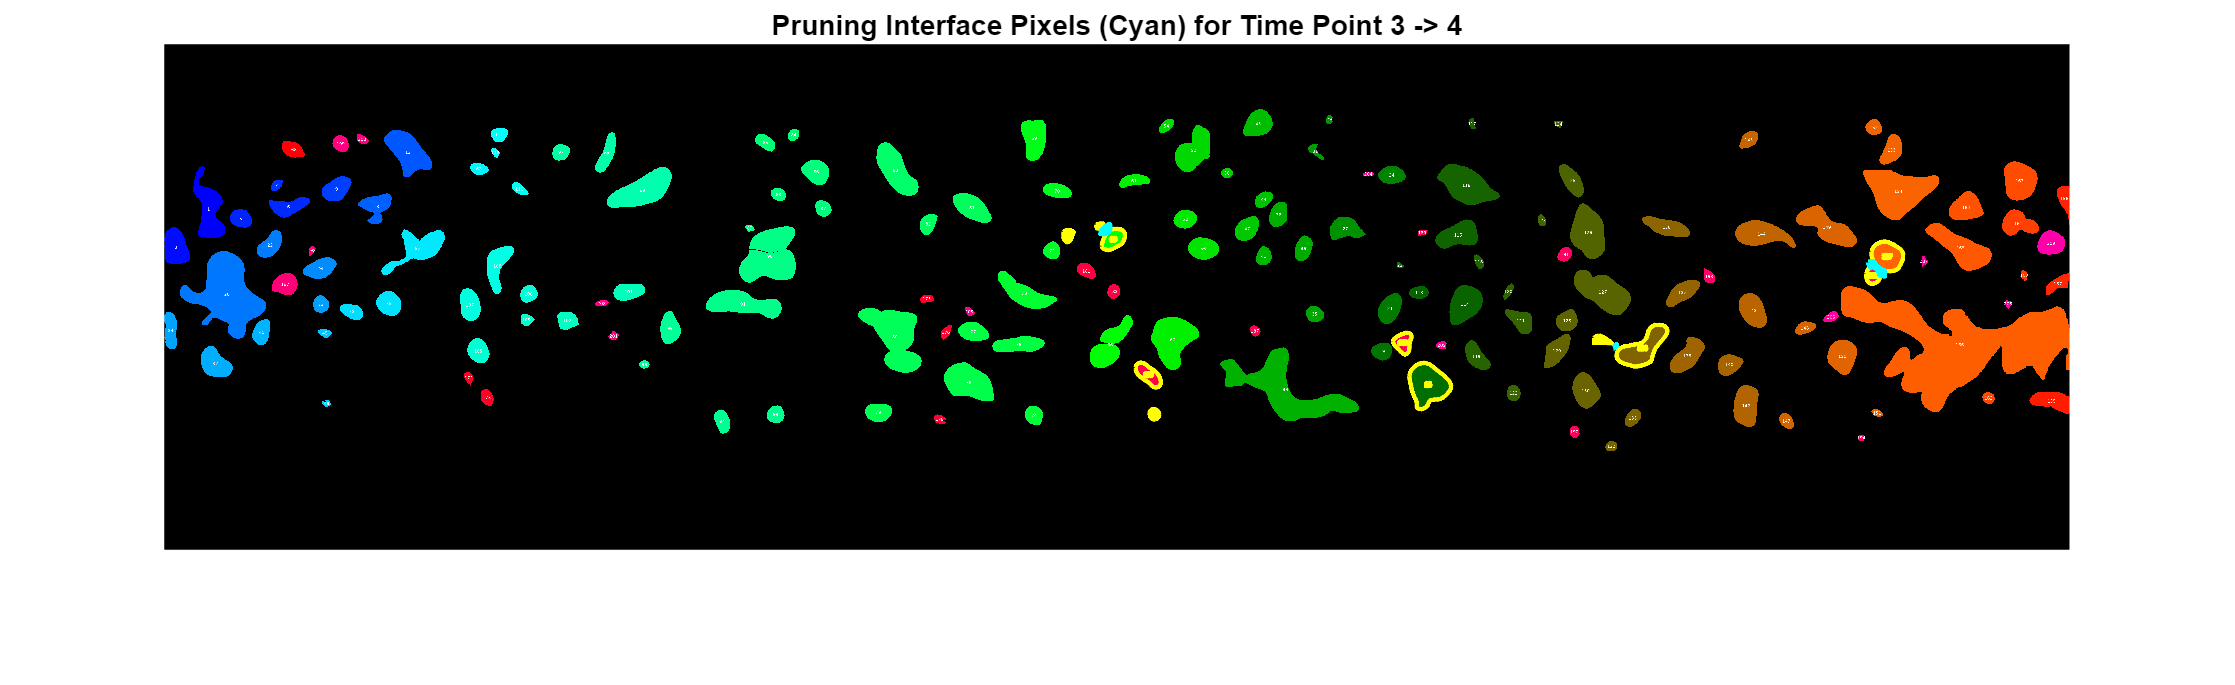

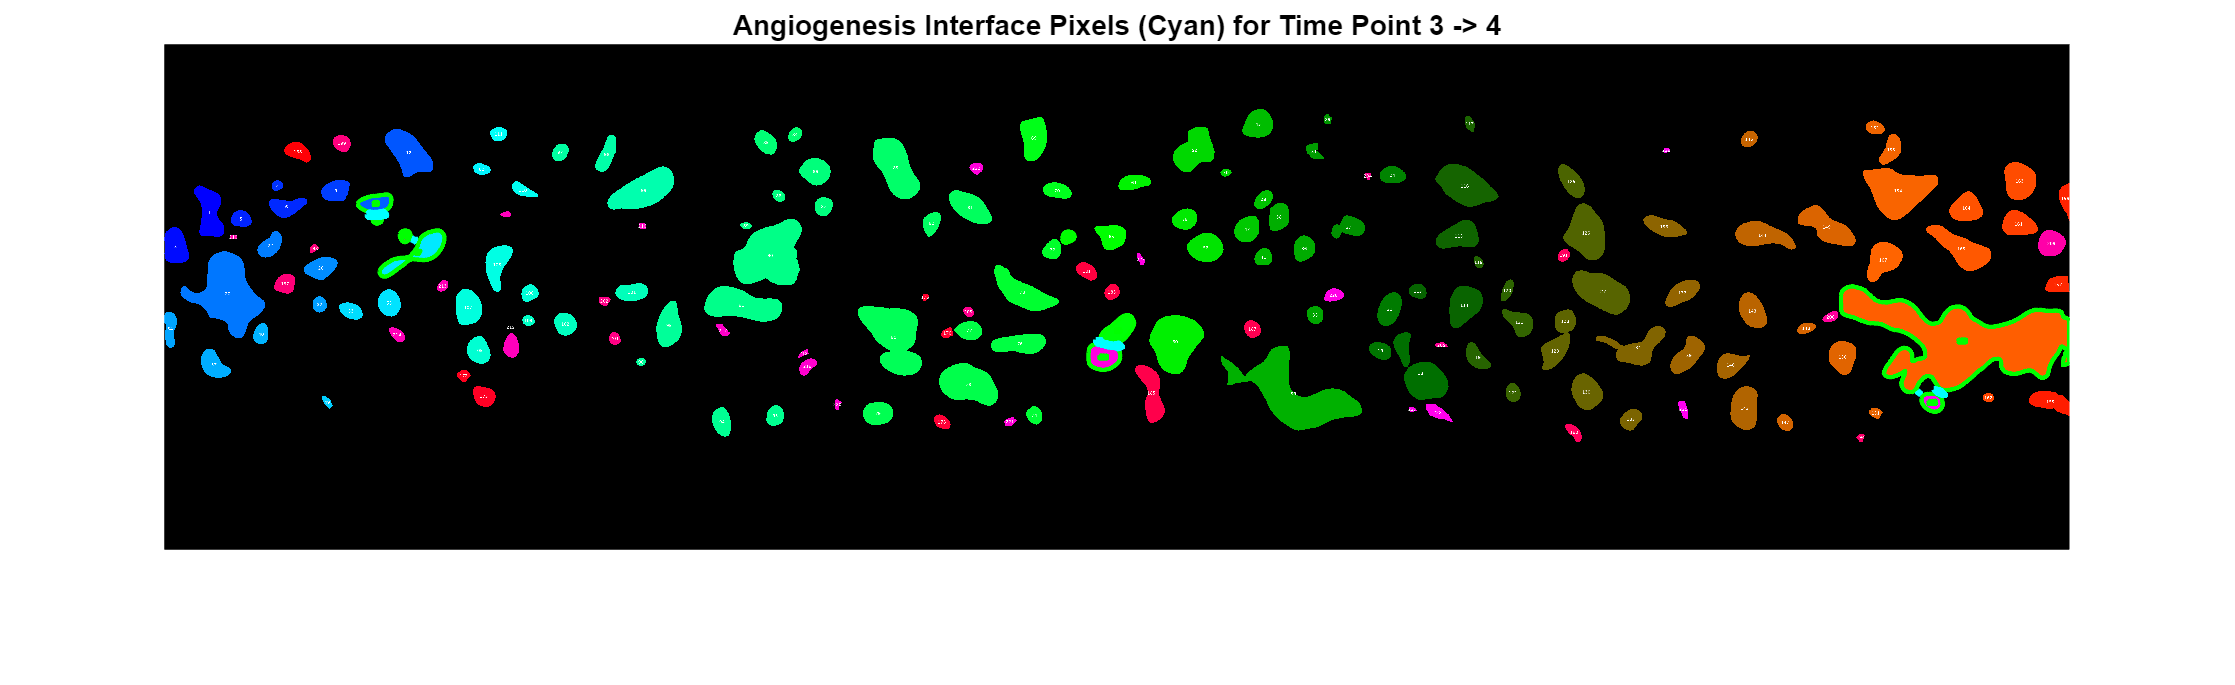

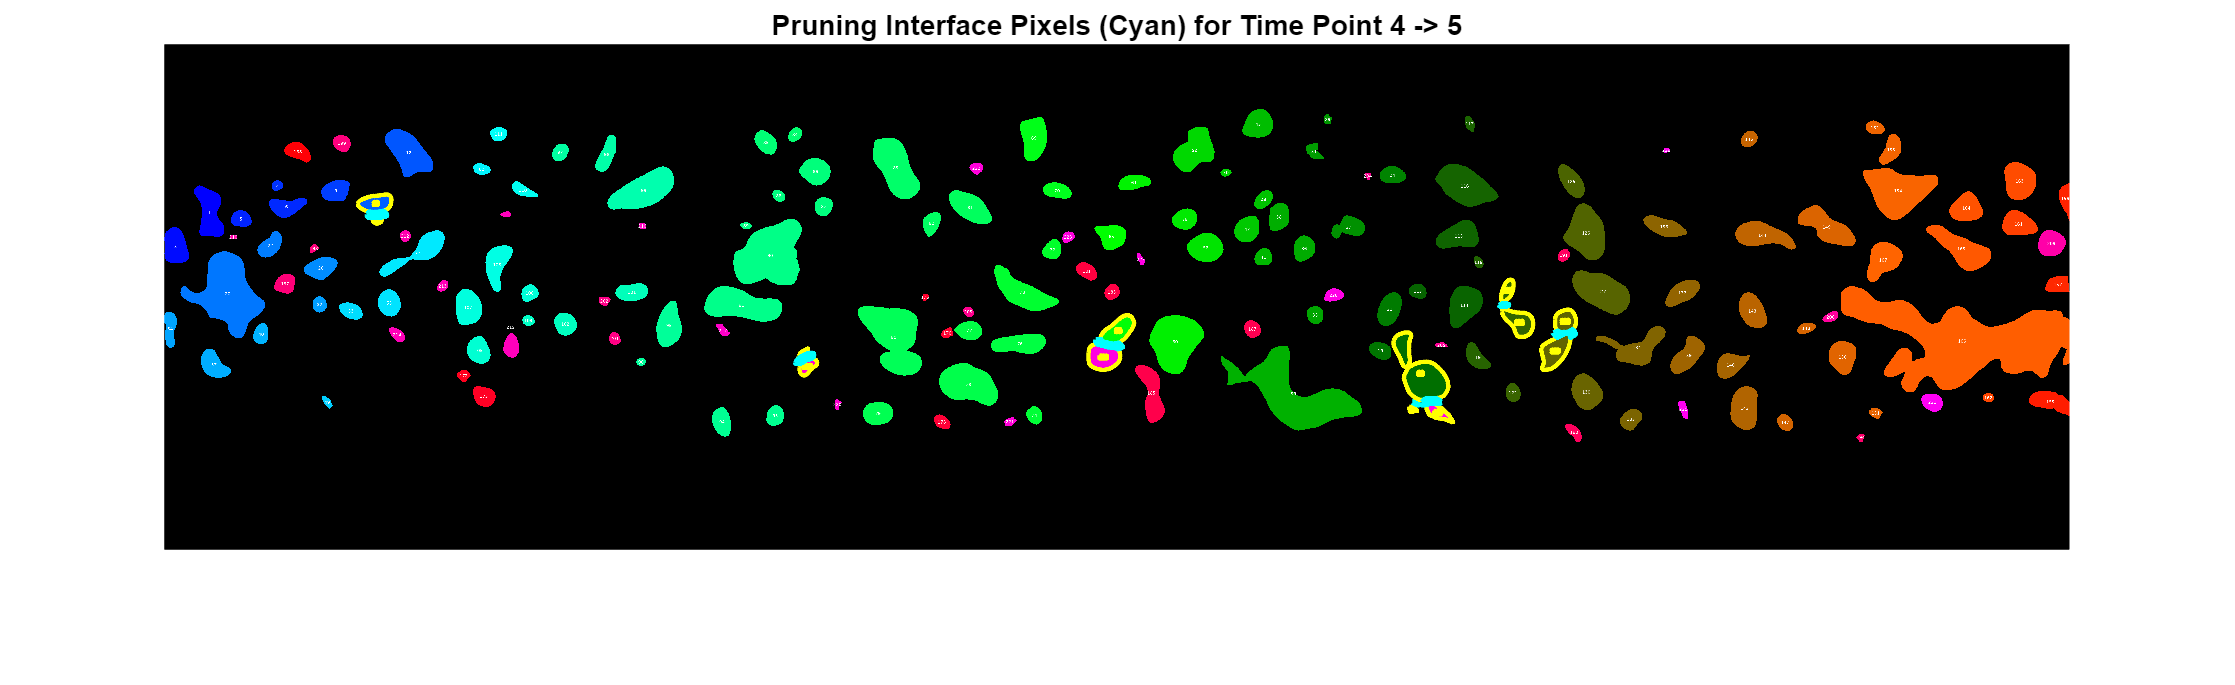

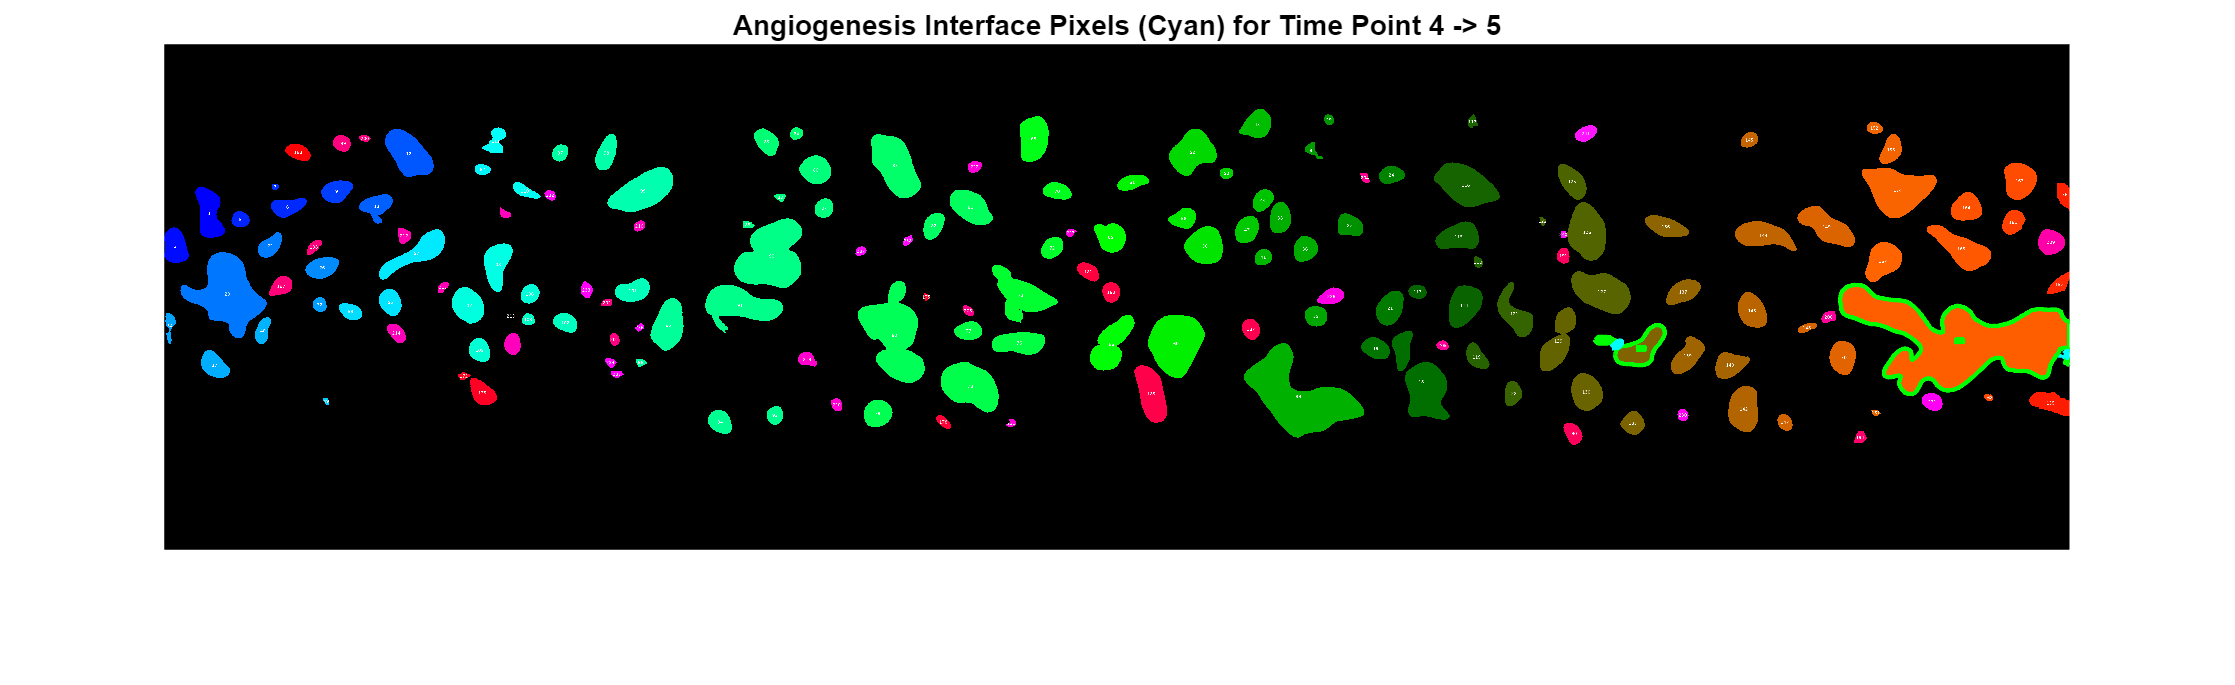



%python again


%{
import pandas as pd
import re

# List of input CSV files
file_list = [
    'vanishing_event_summary_1_2.csv',
    'vanishing_event_summary_2_3.csv',
    'vanishing_event_summary_3_4.csv',
    'vanishing_event_summary_4_5.csv',
    'vanishing_event_summary_5_6.csv',
    'vanishing_event_summary_6_7.csv'
]

# Initialize an empty list to store summary data
compact_summary = []

# Process each file
for file in file_list:
    df = pd.read_csv(file)

    # Extract timepoint in the format "Timepoint 1+2" using regex
    match = re.search(r'(\d+)_(\d+)', file)
    if match:
        timepoint = f"Timepoint {match.group(1)}+{match.group(2)}"
    else:
        raise ValueError(f"Could not extract timepoints from filename: {file}")

    # Convert X_Coordinates column from string to list of numbers
    df['X_Coordinates'] = df['X_Coordinates'].apply(lambda x: list(map(int, x.strip('[]').split())) if 'No coordinates' not in x else [])

    # Get unique x-values
    unique_x_values = sorted(set(x for sublist in df['X_Coordinates'] for x in sublist))

    # Store the compact summary
    compact_summary.append([timepoint, unique_x_values])

# Convert to DataFrame
compact_df = pd.DataFrame(compact_summary, columns=['Timepoints', 'Unique_X_Coordinates'])

# Save the compact summary to CSV
compact_file_path = 'compact_vanishing.csv'
compact_df.to_csv(compact_file_path, index=False)

print(f'Compact vanishing summary saved as {compact_file_path}')
%}


%{

% Load and process compact summary
compact_data = readtable('compact_vanishing.csv');

% Extract unique timepoints and coordinates
timepoints = compact_data.Timepoints;
x_coordinates = compact_data.Unique_X_Coordinates;

% Convert x-coordinates from string to numerical arrays
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Remove empty cells and convert remaining ones to numeric arrays safely
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Remove empty cells
x_coords_numeric = x_coords_numeric(~cellfun('isempty', x_coords_numeric));

% Check if the cell array is empty before concatenating
if isempty(x_coords_numeric)
    all_coords = [];
else
    % Flatten the cell array to get all coordinates safely
    all_coords = horzcat(x_coords_numeric{:});
end

% Ensure there's valid data before setting x-axis limits
if ~isempty(all_coords)
    xlim([0 max(all_coords) + 100]);
else
    warning('No valid coordinates found, setting default axis limits.');
    xlim([0 100]);
end

% Define color palette
colors = lines(length(timepoints));

% Create the figure
figure;
hold on;
for t = 1:length(timepoints)
    y_level = length(timepoints) - t + 1; % Stack from top to bottom
    coords = x_coords_numeric{t};

    % Plot vertical bars for each coordinate at the corresponding timepoint level
    for j = 1:length(coords)
        plot([coords(j), coords(j)], [y_level-0.4, y_level+0.4], ...
            'Color', colors(t, :), 'LineWidth', 5); 
    end
end

% Configure plot appearance
yticks(1:length(timepoints));
yticklabels(flip(timepoints));  % Label each stacked axis
xlabel('X-Coordinates (pixels)');
ylabel('Timepoint Pairs');
title('Vanishing Events Visualization');

grid on;
hold off;

disp('Plotting complete.');


%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%{

%%%% Point distribution

% This is supposed to show in a reduced dimension only alongside its x-axis
% we can see then how the area is distributed alongside the x-axis
% is used later on for the event detection, that we also have a
% distribution alongside the x-axis -> can be used to see differences in
% high flow and low flow zone


%it works by slicing the image, so taking every x coordinate and look for
%every y-coordinate, if there is a RGB value =/= 0 0 0, if yes a counter is
%added


for t = 1:numel(file_names)
    
    input_image = imread(file_names{t});
    
   
    [rows, cols, ~] = size(input_image);
    
    
    point_count_by_x = zeros(1, cols);
    
    
    for x = 1:cols
        
        column_rgb_values = input_image(:, x, :);
        
        
        column_rgb_values = reshape(column_rgb_values, rows, 3);
        
        % Check if pixels are not grayscale (where R = G = B)
        is_valid_pixel = ~(column_rgb_values(:, 1) == column_rgb_values(:, 2) & ...
                           column_rgb_values(:, 2) == column_rgb_values(:, 3));

        % Count the number of valid pixels in this x-coordinate slice
        point_count_by_x(x) = sum(is_valid_pixel);
    end

    
    point_counts_all_timepoints{t} = point_count_by_x;

     
    figure;
    plot(1:cols, point_count_by_x, 'LineWidth', 1.5);
    xlabel('X-Coordinate in Image');
    ylabel('Point Count');
    title(sprintf('Point Distribution by X-Coordinate for Time Point %d', t));
    grid on;
end


%last figure is for all timepoints combined, can be a little messy

figure;
hold on;


color_map = jet(numel(file_names));  

for t = 1:numel(file_names)
    plot(1:cols, point_counts_all_timepoints{t}, 'LineWidth', 1.5, 'Color', color_map(t, :), ...
         'DisplayName', sprintf('Time Point %d', t));
end


xlabel('X-Coordinate in Image');
ylabel('Point Count');
title('Point Distribution by X-Coordinate Across All Time Points');
legend('Location', 'Best');
grid on;
hold off;




% Save point distribution data to CSV files
for t = 1:numel(file_names)
    filename = sprintf('point_distribution_timepoint_%d.csv', t);
    writematrix(point_counts_all_timepoints{t}, filename);
    fprintf('Saved point distribution for timepoint %d to %s\n', t, filename);
end

% Combine all timepoints into a single CSV file
all_timepoints_matrix = cell2mat(point_counts_all_timepoints(:)');
writematrix(all_timepoints_matrix, 'combined_point_distribution.csv');
disp('Combined point distribution saved.');

% Save the total sum of all timepoints
total_pixel_count = sum(all_timepoints_matrix, 1);
writematrix(total_pixel_count, 'total_pixel_distribution.csv');
disp('Total pixel distribution saved.');



%}
%%%%%%%%%%%%%%%%%

%{

% all events summed up and all pixels summed up

% Define event types and corresponding file names
event_types = {'pruning', 'angiogenesis', 'spawning', 'vanishing'};
file_names = {'compact_pruning.csv', 'compact_angiogenesis.csv', 'compact_spawning.csv', 'compact_vanishing.csv'};
colors = {'b', 'r', 'g', 'm'};  % Blue, Red, Green, Magenta for different events

for i = 1:numel(event_types)
    % Load the compact event summary CSV file
    compact_data = readtable(file_names{i});

    % Extract x-coordinates and convert from string to numerical arrays
    x_coordinates = compact_data.Unique_X_Coordinates;
    x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

    % Combine all x-coordinates into a single array
    all_event_x_coords = [];
    for t = 1:length(x_coords_numeric)
        all_event_x_coords = [all_event_x_coords, x_coords_numeric{t}];
    end

    % Define x-axis range and bin size (e.g., 50 pixels)
    x_bins = 0:50:max(all_event_x_coords) + 50;

    % Count occurrences in each x-bin
    [counts, bin_edges] = histcounts(all_event_x_coords, x_bins);

    % Plot distribution of events
    figure;
    bar(bin_edges(1:end-1), counts, 'FaceColor', colors{i}, 'EdgeColor', 'k');
    xlabel('X-Coordinate (pixels)');
    ylabel(['Number of ', event_types{i}, ' Events']);
    title(['Distribution of ', event_types{i}, ' Event Occurrences by X-Coordinate']);
    grid on;
    xlim([0 max(all_event_x_coords) + 50]);

    disp([event_types{i}, ' event distribution analysis complete.']);
end

%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%{

%Correlations .. first get point distributions more reliably

% Load pixel distribution files for all timepoints
pixel_files = {
    'point_distribution_timepoint_1.csv',
    'point_distribution_timepoint_2.csv',
    'point_distribution_timepoint_3.csv',
    'point_distribution_timepoint_4.csv',
    'point_distribution_timepoint_5.csv',
    'point_distribution_timepoint_6.csv',
    'point_distribution_timepoint_7.csv'
};

% Load the pruning event data from the compact file
pruning_data = readtable('compact_pruning.csv');

% Extract the unique timepoint pairs and x-coordinates
timepoints = pruning_data.Timepoints;
x_coordinates = pruning_data.Unique_X_Coordinates;

% Convert x-coordinates from string to numerical arrays
x_coords_numeric = cellfun(@(x) str2num(x), x_coordinates, 'UniformOutput', false);

% Initialize an array to store correlation results
correlation_results = zeros(length(timepoints), 1);

% Loop through each timepoint pair
for i = 1:length(timepoints)
    % Load pixel count data for the corresponding timepoint
    pixel_data = readmatrix(pixel_files{i+1});  % Next timepoint data
    
    % Extract x-coordinates of pruning events for this timepoint pair
    event_x_coords = x_coords_numeric{i};
    
    % Count occurrences of pruning events at each x-coordinate
    pruning_event_count = histcounts(event_x_coords, 1:length(pixel_data)+1);
    
    
    pixel_counts_at_events = pixel_data(event_x_coords);
    
    
    figure;
    scatter(pixel_counts_at_events, pruning_event_count(event_x_coords), 'filled');
    xlabel('Pixel Count at X-Coordinate');
    ylabel('Number of Pruning Events');
    title(sprintf('Pruning Events vs. Pixel Count for Timepoint %s', timepoints{i}));
    grid on;

    
    if length(pixel_counts_at_events) > 1
        correlation_results(i) = corr(pixel_counts_at_events', pruning_event_count(event_x_coords)');
        disp(['Correlation for ', timepoints{i}, ': ', num2str(correlation_results(i))]);
    else
        disp(['Not enough data points to compute correlation for ', timepoints{i}]);
    end
end

% Display correlation results
disp('Correlation results across timepoints:');
disp(table(timepoints, correlation_results, 'VariableNames', {'Timepoints', 'Correlation'}));

%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% correlation of different events with each other

%{

event_files = {
    'compact_pruning.csv', 
    'compact_angiogenesis.csv', 
    'compact_spawning.csv', 
    'compact_vanishing.csv'
};

event_names = {'Pruning', 'Angiogenesis', 'Spawning', 'Vanishing'};


event_data = struct();


for i = 1:length(event_files)
    T = readtable(event_files{i});
    x_coords = cellfun(@(x) str2num(x), T.Unique_X_Coordinates, 'UniformOutput', false);
    
    % Flatten all x-coordinates into a single array, handling empty values
    % ??
    
    for i = 1:length(event_names)
        all_x_coords = [];
        for j = 1:length(x_coords)
            if ~isempty(x_coords{j}) && all(~isnan(x_coords{j}))
                all_x_coords = [all_x_coords; x_coords{j}(:)];
            end
        end
        all_x_coords = unique(all_x_coords);  % Ensure unique values
        event_data.(event_names{i}) = all_x_coords;
    end

    
    disp(event_names);
    disp(length(event_names));


    all_x_coords = unique(all_x_coords);  % Ensure unique values
    event_data.(event_names{i}) = all_x_coords;

end


all_x_values = unique([event_data.Pruning; event_data.Angiogenesis; event_data.Spawning; event_data.Vanishing]);


event_matrix = zeros(length(all_x_values), length(event_names));

for i = 1:length(event_names)
    event_matrix(:, i) = ismember(all_x_values, event_data.(event_names{i}));
end


correlation_matrix = corr(event_matrix, 'Type', 'Pearson');


disp('Correlation matrix between event types:');
disp(array2table(correlation_matrix, 'VariableNames', event_names, 'RowNames', event_names));


figure;
gplotmatrix(event_matrix, event_matrix, [], 'rbkm', 'o+*x', [], 'on', event_names, event_names);
title('Correlation Between Event Types by X-Coordinates');


figure;
heatmap(event_names, event_names, correlation_matrix);
title('Event Type Correlation Heatmap');
colormap jet;
colorbar;

disp('Event correlation analysis complete.');


%}

%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% New part from 28.01

% new determination of whole coordinates of events
% way more accurate



%Find interference pixels


% Define parameters and input file details
event_files = dir('timepoint_event_comparison_*.csv');
image_prefix = 'significant_labeled_areas_timepoint_';
image_suffix = '.png';
dilation_radius = 20;  % Adjust this if necessary

% Loop over each timepoint pair
for t = 2:numel(event_files)
    % Read event data and images for the current timepoint pair
    event_data = readtable(event_files(t-1).name);
    prev_image = imread(sprintf('%s%d%s', image_prefix, t-1, image_suffix));
    curr_image = imread(sprintf('%s%d%s', image_prefix, t, image_suffix));

    % --- Process PRUNING events ---
    pruning_data = event_data(strcmp(event_data.Event, 'Pruning'), :);
    pruning_event_list = {};
    figure; imshow(prev_image); hold on;

    % Process each pruning event
    for i = 1:height(pruning_data)
        % Get the RGB values of the pruned cluster
        pruned_rgb = table2array(pruning_data(i, {'R', 'G', 'B'}));

        % Create a mask for the pruned cluster in the previous image
        pruned_mask = all(prev_image == reshape(pruned_rgb, 1, 1, 3), 3);

        % Find sample coordinates to determine the consuming cluster
        [rows, cols] = find(pruned_mask);
        rand_idx = randsample(length(rows), min(5, length(rows)));
        sample_coords = [rows(rand_idx), cols(rand_idx)];

        % Identify the consuming cluster in the second timepoint
        consuming_rgb = [];
        for k = 1:size(sample_coords, 1)
            sample_rgb = squeeze(curr_image(sample_coords(k, 1), sample_coords(k, 2), :))';
            if any(sample_rgb)  % Valid RGB found
                consuming_rgb = sample_rgb;
                break;
            end
        end

        if isempty(consuming_rgb)
            warning('No consuming cluster found for pruned cluster with RGB [%d, %d, %d]', pruned_rgb);
            continue;
        end

        % Create a mask for the consuming cluster in the previous image
        consuming_mask = all(prev_image == reshape(consuming_rgb, 1, 1, 3), 3);

        % Dilate the masks to detect interface
        pruned_mask_dilated = imdilate(pruned_mask, strel('disk', dilation_radius));
        consuming_mask_dilated = imdilate(consuming_mask, strel('disk', dilation_radius));

        % Calculate the interface area
        interface_pixels = pruned_mask_dilated & consuming_mask_dilated & ~(pruned_mask | consuming_mask);

        % Extract the coordinates of interface pixels
        [interface_rows, interface_cols] = find(interface_pixels);
        interface_coords_str = sprintf('(%d, %d) ', [interface_rows, interface_cols]');

        % Add the data to the list
        pruning_event_list = [pruning_event_list; ...
            {sprintf('(%d, %d, %d)', pruned_rgb), sprintf('(%d, %d, %d)', consuming_rgb), interface_coords_str}];

        % Plot the cluster boundaries and interface
        pruned_boundary = bwboundaries(pruned_mask);
        consuming_boundary = bwboundaries(consuming_mask);
        interface_boundary = bwboundaries(interface_pixels);

        % Plot in the visualization
        for k = 1:length(pruned_boundary)
            plot(pruned_boundary{k}(:, 2), pruned_boundary{k}(:, 1), 'y', 'LineWidth', 1.5);
        end
        for k = 1:length(consuming_boundary)
            plot(consuming_boundary{k}(:, 2), consuming_boundary{k}(:, 1), 'y', 'LineWidth', 1.5);
        end
        for k = 1:length(interface_boundary)
            plot(interface_boundary{k}(:, 2), interface_boundary{k}(:, 1), 'c', 'LineWidth', 2);
        end
    end

    title(sprintf('Pruning Interface Pixels (Cyan) for Time Point %d -> %d', t-1, t));
    hold off;

    % Save pruning event data to CSV
    pruning_event_table = cell2table(pruning_event_list, ...
        'VariableNames', {'PrunedClusterRGB', 'ConsumingClusterRGB', 'InterfaceCoordinates'});
    writetable(pruning_event_table, sprintf('pruning_event_interface_timepoint_%d_to_%d.csv', t-1, t));

    % --- Process ANGIOGENESIS events ---
    angiogenesis_data = event_data(strcmp(event_data.Event, 'Angiogenesis'), :);
    angiogenesis_event_list = {};
    figure; imshow(curr_image); hold on;

    % Process each angiogenesis event
    for i = 1:height(angiogenesis_data)
        % Get the RGB values of the new cluster and find the parent cluster
        new_rgb = table2array(angiogenesis_data(i, {'R', 'G', 'B'}));
        new_mask = all(curr_image == reshape(new_rgb, 1, 1, 3), 3);

        % Find sample coordinates to determine the parent cluster
        [rows, cols] = find(new_mask);
        rand_idx = randsample(length(rows), min(5, length(rows)));
        sample_coords = [rows(rand_idx), cols(rand_idx)];

        % Identify the parent cluster in the first timepoint
        parent_rgb = [];
        for k = 1:size(sample_coords, 1)
            sample_rgb = squeeze(prev_image(sample_coords(k, 1), sample_coords(k, 2), :))';
            if any(sample_rgb)  % Valid RGB found
                parent_rgb = sample_rgb;
                break;
            end
        end

        if isempty(parent_rgb)
            warning('No parent cluster found for new cluster with RGB [%d, %d, %d]', new_rgb);
            continue;
        end

        % Create a mask for the parent cluster in the second image
        parent_mask = all(curr_image == reshape(parent_rgb, 1, 1, 3), 3);

        % Dilate both masks to detect interface
        new_mask_dilated = imdilate(new_mask, strel('disk', dilation_radius));
        parent_mask_dilated = imdilate(parent_mask, strel('disk', dilation_radius));

        % Calculate the interface area
        interface_pixels = new_mask_dilated & parent_mask_dilated & ~(new_mask | parent_mask);

        % Extract the coordinates of interface pixels
        [interface_rows, interface_cols] = find(interface_pixels);
        interface_coords_str = sprintf('(%d, %d) ', [interface_rows, interface_cols]');

        % Add the data to the list
        angiogenesis_event_list = [angiogenesis_event_list; ...
            {sprintf('(%d, %d, %d)', parent_rgb), sprintf('(%d, %d, %d)', new_rgb), interface_coords_str}];

        % Plot the cluster boundaries and interface
        new_boundary = bwboundaries(new_mask);
        parent_boundary = bwboundaries(parent_mask);
        interface_boundary = bwboundaries(interface_pixels);

        
        for k = 1:length(new_boundary)
            plot(new_boundary{k}(:, 2), new_boundary{k}(:, 1), 'g', 'LineWidth', 1.5);
        end
        for k = 1:length(parent_boundary)
            plot(parent_boundary{k}(:, 2), parent_boundary{k}(:, 1), 'g', 'LineWidth', 1.5);
        end
        for k = 1:length(interface_boundary)
            plot(interface_boundary{k}(:, 2), interface_boundary{k}(:, 1), 'c', 'LineWidth', 2);
        end
    end

    title(sprintf('Angiogenesis Interface Pixels (Cyan) for Time Point %d -> %d', t-1, t));
    hold off;
    
    if ~isempty(angiogenesis_event_list)
        
        try
            angiogenesis_event_table = cell2table(angiogenesis_event_list, ...
                'VariableNames', {'ParentClusterRGB', 'NewClusterRGB', 'InterfaceCoordinates'});
        catch ME
            
            disp('Error creating the angiogenesis event table:');
            disp(ME.message);
           
            disp('Structure of angiogenesis_event_list:');
            disp(angiogenesis_event_list);
            return;
        end
    
        
        writetable(angiogenesis_event_table, sprintf('angiogenesis_event_interface_timepoint_%d_to_%d.csv', t-1, t));
    else
        warning('No angiogenesis events found for Time Point %d -> %d', t-1, t)
    end

end





%% For Spawning and Vanishing it is way easier to extract the relevant
%% pixels, since it is always just the whole cluster 

% Initialization for spawning and vanishing events

% Get list of event CSV files
event_files = dir('timepoint_event_comparison_*.csv');
image_prefix = 'significant_labeled_areas_timepoint_';
image_suffix = '.png';

% Loop over each timepoint pair
for t = 2:numel(event_files)
    % Read event data for the current timepoint pair
    event_data = readtable(event_files(t-1).name);

    % Read the images for the two timepoints
    prev_image = imread(sprintf('%s%d%s', image_prefix, t-1, image_suffix));
    curr_image = imread(sprintf('%s%d%s', image_prefix, t, image_suffix));

    % Extract the spawning and vanishing events
    spawning_data = event_data(strcmp(event_data.Event, 'Spawning'), :);
    vanishing_data = event_data(strcmp(event_data.Event, 'Vanishing'), :);

    % Initialize lists for event data storage
    spawning_event_list = {};
    vanishing_event_list = {};

    %% --- Process Spawning Events ---
    for i = 1:height(spawning_data)
        % Extract the RGB value for the spawning cluster
        spawning_rgb = table2array(spawning_data(i, {'R', 'G', 'B'}));

        % Create a mask for the spawning cluster in the current image
        spawning_mask = all(curr_image == reshape(spawning_rgb, 1, 1, 3), 3);

        % Extract the coordinates of the spawning cluster pixels
        [spawning_rows, spawning_cols] = find(spawning_mask);
        spawning_coords = [spawning_rows, spawning_cols];

        % Store the spawning event data
        spawning_event_list{end+1, 1} = spawning_rgb;  % RGB value of the spawning cluster
        spawning_event_list{end, 2} = arrayfun(@(r, c) sprintf('(%d, %d)', r, c), spawning_coords(:, 1), spawning_coords(:, 2), 'UniformOutput', false);
    end

    %% --- Process Vanishing Events ---
    for i = 1:height(vanishing_data)
        % Extract the RGB value for the vanishing cluster
        vanishing_rgb = table2array(vanishing_data(i, {'R', 'G', 'B'}));

        % Create a mask for the vanishing cluster in the previous image
        vanishing_mask = all(prev_image == reshape(vanishing_rgb, 1, 1, 3), 3);

        % Extract the coordinates of the vanishing cluster pixels
        [vanishing_rows, vanishing_cols] = find(vanishing_mask);
        vanishing_coords = [vanishing_rows, vanishing_cols];

        % Store the vanishing event data
        vanishing_event_list{end+1, 1} = vanishing_rgb;  % RGB value of the vanishing cluster
        vanishing_event_list{end, 2} = arrayfun(@(r, c) sprintf('(%d, %d)', r, c), vanishing_coords(:, 1), vanishing_coords(:, 2), 'UniformOutput', false);
    end

    %% --- Save Spawning and Vanishing Events to CSV ---
    
    % Spawning CSV
    spawning_event_table = cell2table(spawning_event_list, 'VariableNames', {'RGB', 'Coordinates'});
    writetable(spawning_event_table, sprintf('spawning_event_coordinates_timepoint_%d_to_%d.csv', t-1, t));

    % Vanishing CSV
    vanishing_event_table = cell2table(vanishing_event_list, 'VariableNames', {'RGB', 'Coordinates'});
    writetable(vanishing_event_table, sprintf('vanishing_event_coordinates_timepoint_%d_to_%d.csv', t-1, t));
end
